# **Observing others give & take: a computational account of bystanders’ feelings and actions**

Bastien Blain1v*, Joseph Marks1v, Philipp Czech1,2, Tali Sharot1,3*

1Affective Brain Lab, Experimental Psychology, University College London, London, UK

2Berlin School of Mind and Brain, Humboldt-Universität zu Berlin, Berlin, Germany

3The Max Planck UCL Centre for Computational Psychiatry and Ageing Research, University College London, London, UK

v Equal contribution

*Corresponding authors: [t.sharot@ucl.ac.uk](mailto:t.sharot@ucl.ac.uk) , bastien.blain@ucl.ac.uk 

*Feel free to use any part of this code for your own research, but please quote this paper.*

# */!\This is the script for the results and figure in the main manuscript /!\*

## **Observers’ affective responses are influenced by observed selfishness and inequality**

%clear everithing
clear all
close all
clc
%load the data
load('Experiment1.mat')
load('Experiment2.mat')
AllPunishmentData1 = [PunishmentData1; FeelingsData1(:,[1:3 11:12 6:8 13:14])];

### **Anovas**

%% Experiment 1
sublength = (length(unique(FeelingsData1.ID)));
% Feelings means
[meanfeelingsExp1Tmp,grpsExp1] = grpstats(FeelingsData1.Feel1,{FeelingsData1.Allocator,FeelingsData1.ID},{'mean','gname'});
grpsExp1=cellfun(@str2double,grpsExp1);
for i = [2 0 1]
    meanfeelingsExp1(1:sublength,i+1) = meanfeelingsExp1Tmp((grpsExp1(:,1))==i);
end
grpsExp1(:,1) = grpsExp1(:,1)+1;
rmANOVAs.feelings1 = [meanfeelingsExp1Tmp grpsExp1];
rmANOVAs.partialeta.feelings1 = 97.594 / (97.594 + 67.892);
% One-sample t-tests
[h,p,ci,stats] = ttest(meanfeelingsExp1(:,3));
CohensD.Feelings1.OneSample.Selfish = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanfeelingsExp1(:,2));
CohensD.Feelings1.OneSample.Equal = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanfeelingsExp1(:,1));
CohensD.Feelings1.OneSample.Generous = stats.tstat/sqrt(sublength);
% Paired-samples t-tests
[h,p,ci,stats] = ttest(meanfeelingsExp1(:,1),meanfeelingsExp1(:,2));
CohensD.Feelings1.PairedSamples.GenerousEqual = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanfeelingsExp1(:,1),meanfeelingsExp1(:,3));
CohensD.Feelings1.PairedSamples.GenerousSelfish = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanfeelingsExp1(:,2),meanfeelingsExp1(:,3));
CohensD.Feelings1.PairedSamples.EqualSelfish = stats.tstat/sqrt(sublength);

%%Experiment 2
sublength = (length(unique(FeelingsData2.ID)));
%Feelings means
[meanfeelingsExp2Tmp,grpsExp2] = grpstats(FeelingsData2.Feel1,{FeelingsData2.Allocator,FeelingsData2.ID},{'mean','gname'});
grpsExp2=cellfun(@str2double,grpsExp2);
for i = [2 0 1]
    meanfeelingsExp2(1:sublength,i+1) = meanfeelingsExp2Tmp((grpsExp2(:,1))==i);
end
grpsExp2(:,1) = grpsExp2(:,1)+1;
rmANOVAs.feelings2 = [meanfeelingsExp2Tmp grpsExp2];
%RMAOV1(rmANOVAs.feelings2)
rmANOVAs.partialeta.feelings2 = 123.108 / (123.108 + 122.328);

% One-sample t-tests
[h,p,ci,stats] = ttest(meanfeelingsExp2(:,3));
CohensD.Feelings2.OneSample.Selfish = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanfeelingsExp2(:,2));
CohensD.Feelings2.OneSample.Equal = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanfeelingsExp2(:,1));
CohensD.Feelings2.OneSample.Generous = stats.tstat/sqrt(sublength);
% Paired-samples t-tests
[h,p,ci,stats] = ttest(meanfeelingsExp2(:,1),meanfeelingsExp2(:,2));
CohensD.Feelings2.PairedSamples.GenerousEqual = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanfeelingsExp2(:,1),meanfeelingsExp2(:,3));
CohensD.Feelings2.PairedSamples.GenerousSelfish = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanfeelingsExp2(:,2),meanfeelingsExp2(:,3));
CohensD.Feelings2.PairedSamples.EqualSelfish = stats.tstat/sqrt(sublength);



#### Figure 2. **Feelings are negative when observing selfish behavior, positive when observing fair acts, and neutral when observing generosity.**

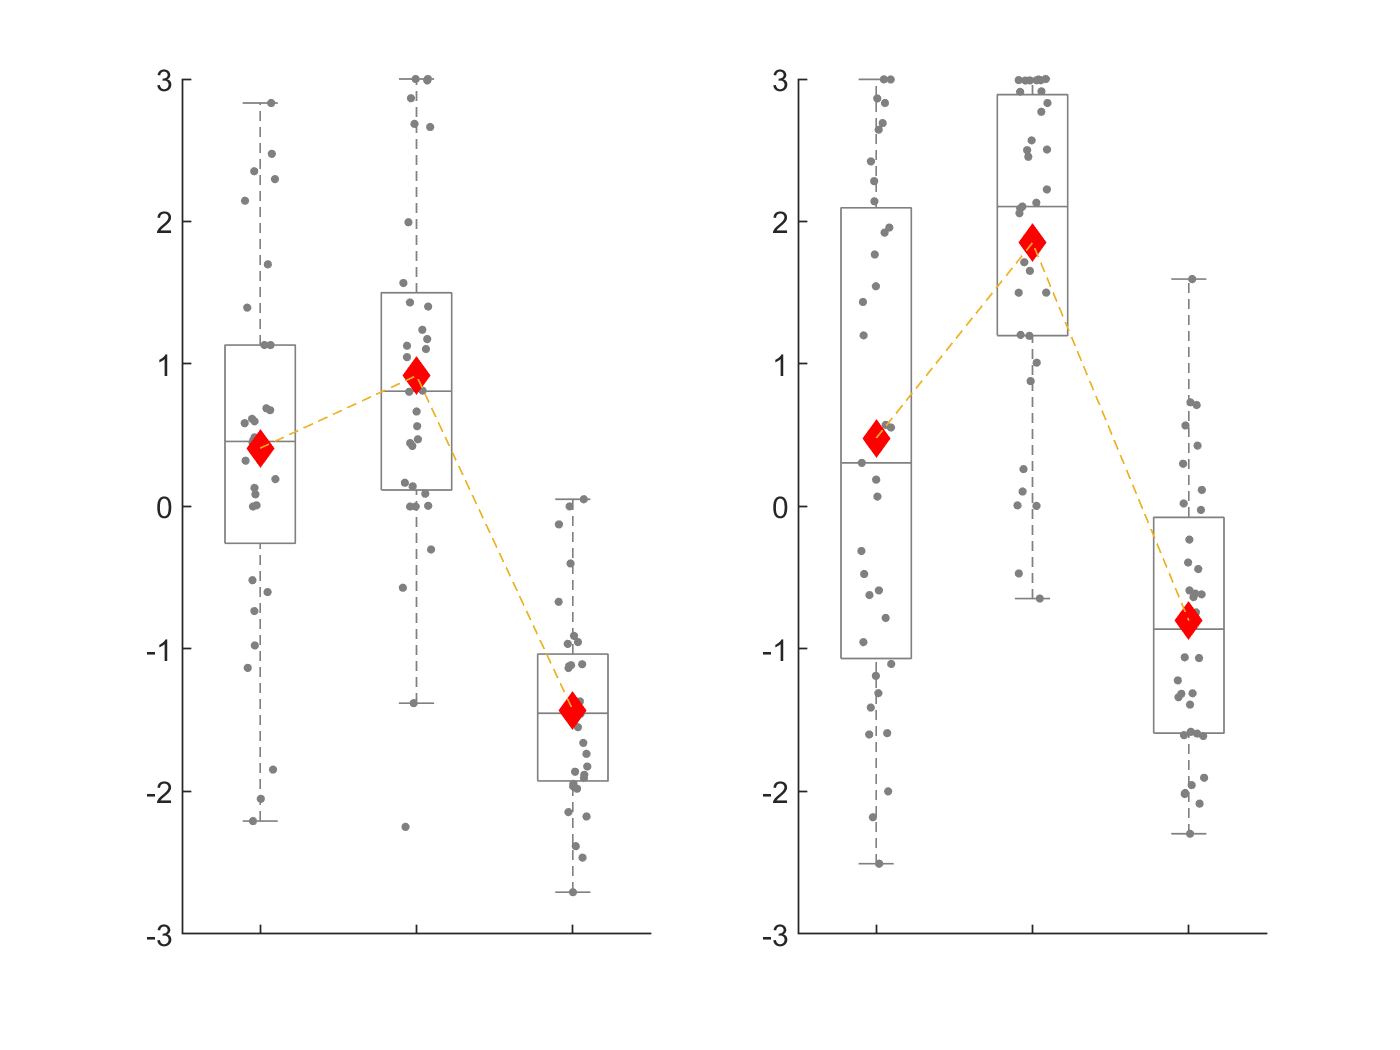

figure;
%% Experiment 1
% Plot
subplot(1,2,1)
boxplot(meanfeelingsExp1,'Colors',[0.5 0.5 0.5],'Symbol','')
sz = 4;
hold on
scatter(grpsExp1(:,1)-.1+rand(length(grpsExp1(:,1)),1)/5,meanfeelingsExp1Tmp,sz,'filled','MarkerEdgeColor',[.5 .5 .5],...
              'MarkerFaceColor',[.5 .5 .5])
ax = gca;
%ax.XLim = [0 4];
ax.YLim = [-3 3];
xticks([1,2,3]);
xticklabels({' ',' ',' '})
set(gca,'box','off');
set(gcf,'color','w');
hold on
plot(1:3,mean(meanfeelingsExp1), 'dr','MarkerSize',8,'MarkerFaceColor','r')
plot(1:3,mean(meanfeelingsExp1),'--')
hold off

%% Experiment 2
subplot(1,2,2)
boxplot(meanfeelingsExp2,'Colors',[0.5 0.5 0.5],'Symbol','')
sz = 4;
hold on
scatter(grpsExp2(:,1)-.1+rand(length(grpsExp2(:,1)),1)/5,meanfeelingsExp2Tmp,sz,'filled','MarkerEdgeColor',[.5 .5 .5],...
              'MarkerFaceColor',[.5 .5 .5])
ax = gca;
%ax.XLim = [0 4];
ax.YLim = [-3 3];
xticks([1,2,3]);
xticklabels({' ',' ',' '})
set(gca,'box','off');
set(gcf,'color','w');
hold on
plot(1:3,mean(meanfeelingsExp2), 'dr','MarkerSize',8,'MarkerFaceColor','r')
plot(1:3,mean(meanfeelingsExp2),'--')
hold off

**Fig 3. Operationalizing selfishness and inequality. **

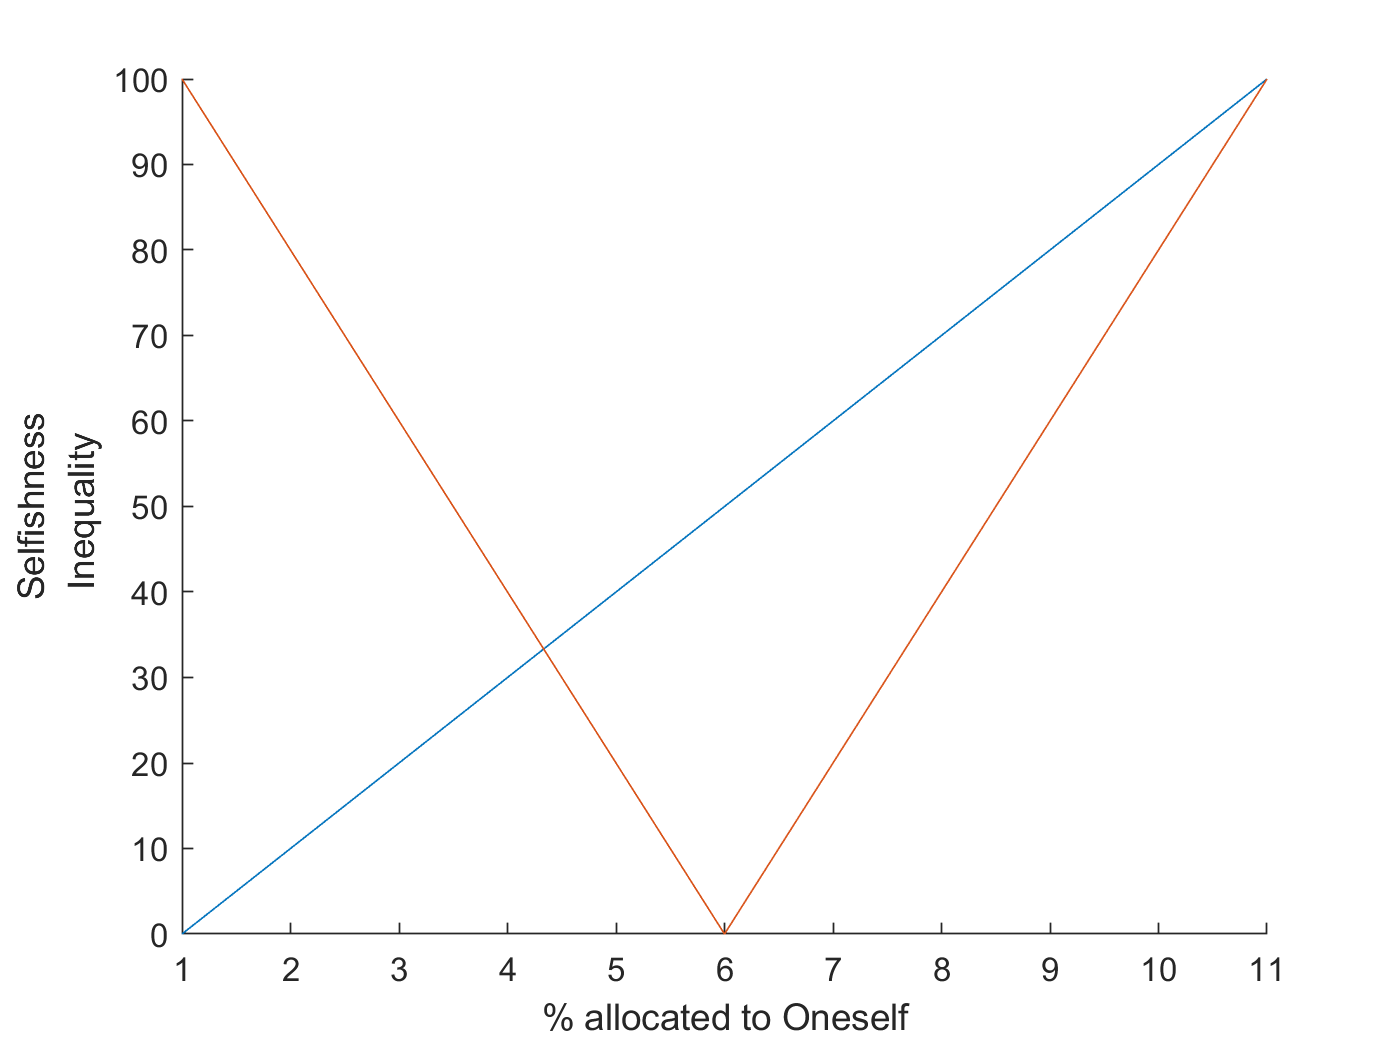

selfishness = 0:10:100;
inequality = abs(selfishness-50)/0.5;
figure;hold on;
plot(selfishness)
plot(inequality)
xlabel('% allocated to Oneself')
ylabel('Selfishness\newline Inequality')

**Model fit for both experiments and both measures**

warning off %(missing data for one participant generate unaesthetic error message. Feel free to uncomment. 
for iExp=1:4% 1 is feeling exp 1, 2 is feeling exp2, 3 is punishement exp 1, 4 is punishment exp 2
    if sum(iExp==[1,3])==1
        sublength = (length(unique(FeelingsData1.ID)));
    else
        sublength = (length(unique(FeelingsData2.ID)));
    end     
    for i = 1:sublength    

Get this subject data

        if iExp==1
            % extract  selfishness, inequality, endowment, and z-scored
            % feelings from experiment 1
            data_ID_i = double(FeelingsData1(FeelingsData1.ID==i,[6,8,7,5]));
        elseif iExp==2
             % extract  selfishness, inequality, endowment, and z-scored
            % feelings from experiment 2
            data_ID_i = double(FeelingsData2(FeelingsData2.ID==i,[6,8,7,5]));
         elseif iExp==3
             % extract  selfishness, inequality, endowment, and z-scored
            % punishment from experiment 1 (from all blocks, see the SuppAnalysesCode without
            % them)
            data_ID_i = double(AllPunishmentData1(AllPunishmentData1.ID==i,[6,8,7,5]));%double(PunishmentData1(PunishmentData1.ID==i,[6,8,7,5]));
         elseif iExp==4
             % extract  selfishness, inequality, endowment, and z-scored
            % punishment from experiment 2
            data_ID_i = double(PunishmentData2(PunishmentData2.ID==i,[6,8,7,5]));
        end
        data_ID_iC = data_ID_i(:,1:4); % concatenate the new matrix
        data_ID_iC(:,5) = (data_ID_iC(:,1)==50);% create the stick function     

Get all the nested models

        X = [data_ID_iC(:,1:2) data_ID_iC(:,1).*data_ID_iC(:,3) data_ID_iC(:,2).*data_ID_iC(:,3)  ];
        
        nObs   = size(X,1); % # observations
        nReg   = size(X(nObs,:),2); % # regressors
        y      = data_ID_iC(1:nObs,4); % dependent variable to fit
        
        % get all the combinations        
        nComb = 0;
        for iComb = 1:(nReg)% compute the number of combination (minus the constant term)
            nComb = nComb + nchoosek((nReg),iComb);
        end
        % initiliase
        matComb  = cell(nComb,1);
        matParamTmp = zeros(nComb,nReg);
        % get the actual combinations
        iComb    = 0;
        for iReg=1:(nReg)
            matComb{iReg} = nchoosek(1:(nReg),iReg);
            for iModel=1:size(matComb{iReg},1)
                iComb = iComb + 1;
                matParamTmp(iComb,[1 matComb{iReg}(iModel,:)+1]) = 1;
            end
        end
        matParamTmp(:,1) = []; % remove the constant
        % add the stick models to the model space 
        X = [X data_ID_iC(:,5)];
        matParamSimple= [matParamTmp zeros(size(matParamTmp,1),1)];
        matParamStick = [matParamTmp ones(size(matParamTmp,1),1)];
        matParam = [matParamSimple;matParamStick;];        
        % normalise the data
        X = X./max(X);
        % independent variable matrix
        matIV  = [(X)]; % independent variables
        nReg   = size(matIV(nObs,:),2); % # regressors  


Estimate each model

        for iModel = 1:size(matParam,1)
            [mu, dev, stats] = glmfit(matIV(:,find(matParam(iModel,:))),y);
            % get the estimates
            estimates{iExp,i,iModel}.muPhi = zeros(nReg+1,1);
            estimates{iExp,i,iModel}.muPhi(find(logical([1 matParam(iModel,:)])),1) = mu;
            %matMuLL(i,iModel,:) = estimates{i,iModel}.muPhi;
            estimates{iExp,i,iModel}.sigmaPhi = zeros(nReg+1);
            tmp = zeros(1,nReg+1);
            tmp(find(logical([1 matParam(iModel,:)]))) = diag(stats.covb);
            estimates{iExp,i,iModel}.sigmaPhi(boolean(eye(nReg+1))) = tmp;
            % get the log likelihood (this is for a normal distribution only)
            sigma(i,iModel)       = sqrt(mean(stats.resid.^ 2)); % maximum likelihood estimate of the standard deviation
            ll(i,iModel)  = sum(-0.5 * (stats.resid/sigma(i,iModel)).^ 2 - log(sqrt(2*pi)*sigma(i,iModel)));
            BIC{iExp}(i,iModel) = sum([1 matParam(iModel,:)]==1).*log(size(y,1))-2.*ll(i,iModel);
            SSres = sum(stats.resid.^2);
            SStot = sum((y-mean(y)).^2);
            matR2{iExp}(i,iModel) = 1-(SSres/SStot);
            modelFitSummary{iExp}(i,iModel,:) = [sum(matParam(iModel,:))+1  matR2{iExp}(i,iModel)  BIC{iExp}(i,iModel)];
            predG{iExp,i,iModel} = estimates{iExp,i,iModel}.muPhi(1) + matIV(:,find(matParam(iModel,:)))* estimates{iExp,i,iModel}.muPhi(logical([0 matParam(iModel,:)]));
        end
        

Do model recovery

        for iModel = 1:size(matParam,1)% loop through each generative model
            % get the model prediction and add noise to it
            pred{i,iModel} = estimates{iExp,i,iModel}.muPhi(1) + matIV(:,find(matParam(iModel,:)))* estimates{iExp,i,iModel}.muPhi(logical([0 matParam(iModel,:)])) + sigma(i,iModel).*rand(size(X,1),1);
            for mModel = 1:size(matParam,1)% loop through each model to fit
                [mu, dev, stats] = glmfit(matIV(:,find(matParam(mModel,:))),pred{i,iModel});
                % get the estimates
                estimatesR{iExp,i,iModel,mModel}.muPhi = zeros(nReg+1,1);
                estimatesR{iExp,i,iModel,mModel}.muPhi(find(logical([1 matParam(mModel,:)])),1) = mu;
                estimatesR{iExp,i,iModel,mModel}.sigmaPhi = zeros(nReg+1);
                tmp = zeros(1,nReg+1);
                tmp(find(logical([1 matParam(mModel,:)]))) = diag(stats.covb);
                estimatesR{iExp,i,iModel,mModel}.sigmaPhi(boolean(eye(nReg+1))) = tmp;
                % get the log likelihood (this is for a normal distribution only)
                sigmaR       = sqrt(mean(stats.resid.^ 2)); % maximum likelihood estimate of the standard deviation
                llR(i,iModel,mModel)  = sum(-0.5 * (stats.resid/sigmaR).^ 2 - log(sqrt(2*pi)*sigmaR));
                BICR{iExp}(i,iModel,mModel) = sum([1 matParam(mModel,:)]==1).*log(size(y,1))-2.*llR(i,iModel,mModel);
                logModelEvidenceLLR(i,iModel,mModel) = -BICR{iExp}(i,iModel,mModel);
            end           
        end
    end
end

**Fig 4. Model specification (A) and model comparision for Experiment 1 (B) and 2 (C)**

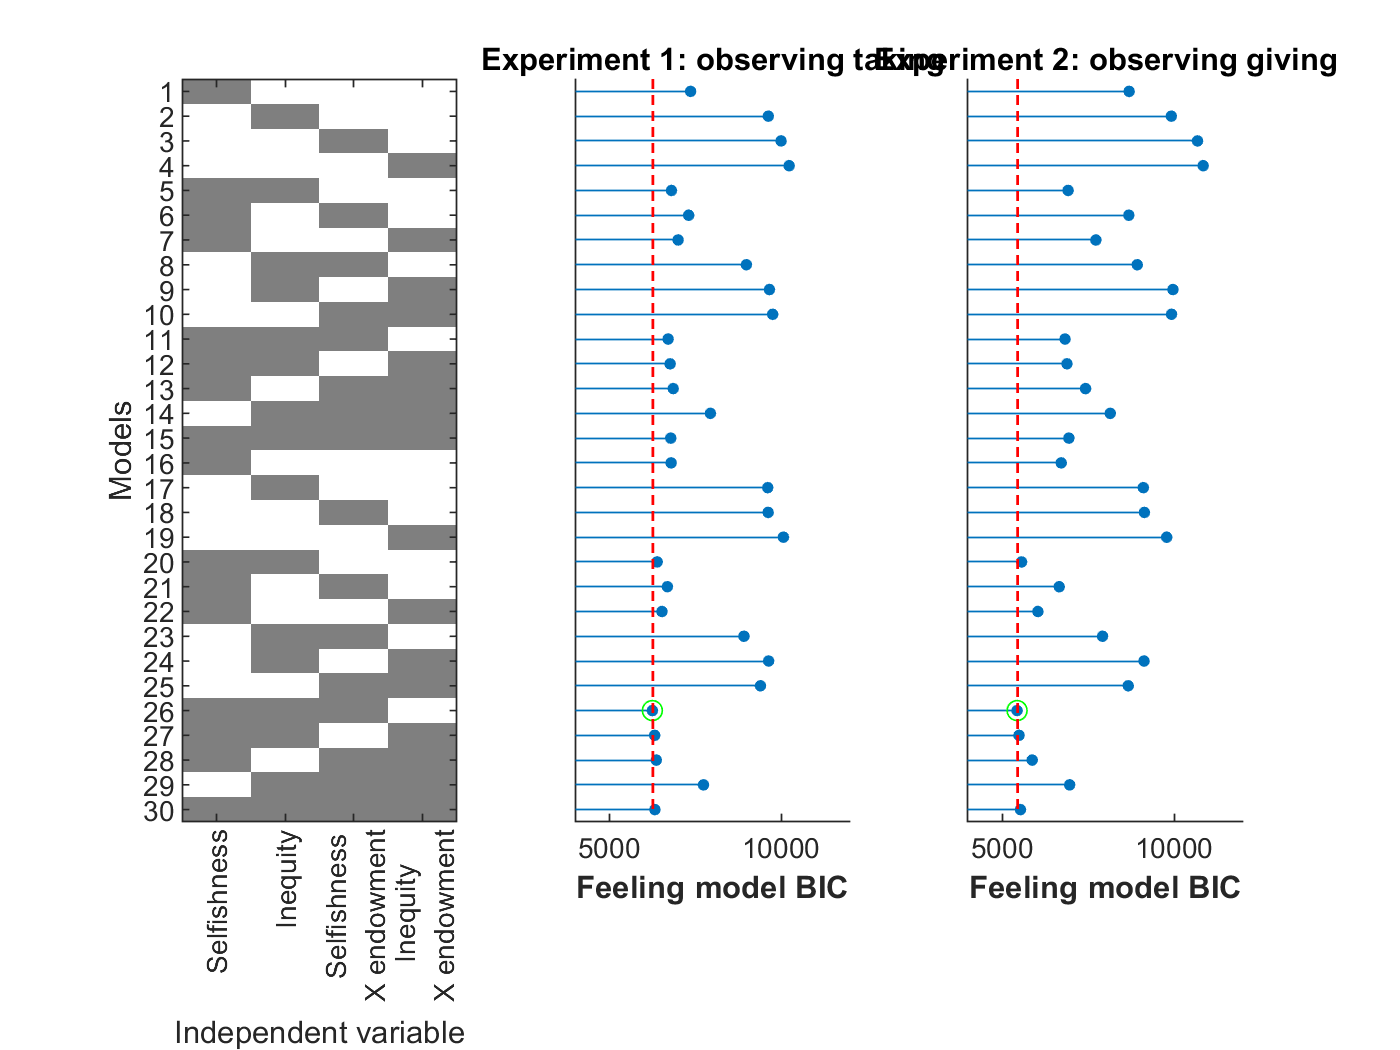

nModel = size(matParam,1);% get the total number models
map = [1   1  1;
      0.5 0.5 0.5];% create a colormap
figure;
c=0;
for iExp=[0 1 2]
    if c==0 %plot the model space
        subplot(1,3,1)
        imagesc(matParam(:,1:(end-1)));
        colormap(map)
        c=c+1;
        xlabel('Independent variable')
        ylabel('Models')
        set(gca,'XTick',1:5,'YTick',1:size(matParam,1),'YTickLabel',num2str([1:1:size(matParam,1)]'),'XTickLabel',{'Selfishness','Inequity','    Selfishness\newline X endowment','      Inequity\newline X endowment','50% stick'},...
            'XTickLabelRotation',90)        
        set(gca,'Clipping','Off')
        for i=1:nModel
            h = line([0 iModel+0.5],[300 iModel+0.5]);
            set(h,'LineWidth',2)
        end
    else %plot the model BICs
        c=c+1;
        BICall = nansum(BIC{iExp},1);%get the BIC sum per model
        subplot(1,3,c);hold on;
        bestModel(iExp) = find(BICall==min(BICall));%select the best model
        stem(BICall,'filled','MarkerSize',3);% plot them all
        plot(bestModel(iExp),min(BICall),'go')% highlight the winning model
        plot([0 nModel],[min(BICall) min(BICall)],'r--')% add line to compare the models
        plot([0 nModel],[min(BICall)+30 min(BICall)+30],'r--')% add line to compare the models
        ylabel('\bf{Feeling} model BIC')
        if iExp==1
            title('Experiment 1: observing taking')
        elseif iExp==2
            title('Experiment 2: observing giving')
        end
        ylim([4000 12000])
        xlim([0.5 nModel+0.5])
        set(gca,'XTick',[],'XTickLabelRotation',0,'XTickLabel','')
        set(gca,'view',[90 -90],'XDir','reverse')
    end
end

Get the corresponding table

idxS=[];
modelNumber = [1:size(matParam,1)]';
for iExp=1:2
    [sBIC, idxS] = sort(nansum(BIC{iExp},1));
    for iModel=1:nModel
        ranking{iExp}(iModel) = find(idxS==iModel);
    end
    parameterNumber = nanmean(modelFitSummary{iExp}(:,:,1),1)';
    r2= nanmean(modelFitSummary{iExp}(:,:,2),1)';
    bic = nansum(modelFitSummary{iExp}(:,:,3),1)';
    rank = ranking{iExp}';
    t = table(modelNumber,parameterNumber,r2,bic,rank);
    modelComparisonTable{iExp} = t;   
end
disp('Feeling,Experiment 1')

Feeling,Experiment 1


disp(modelComparisonTable{1})

    modelNumber    parameterNumber      r2        bic      rank
    ___________    _______________    _______    ______    ____

         1                2           0.51387      7362     16 
         2                2           0.28795      9623     24 
         3                2           0.23017    9993.6     28 
         4                2           0.18253     10230     30 
         5                3           0.61257    6805.7     12 
         6                3             0.535      7306     15 
         7                3           0.58604    6999.3     14 
         8                3            0.4147    8986.2     20 
         9                3           0.30531    9657.6     26 
        10                3            0.3022    9750.4     27 
        11                4           0.63168    6708.6      

disp('Feeling,Experiment 2')

Feeling,Experiment 2


disp(modelComparisonTable{2})

    modelNumber    parameterNumber      r2        bic      rank
    ___________    _______________    _______    ______    ____

         1                2           0.43042    8687.3     20 
         2                2           0.32615    9914.1     26 
         3                2           0.22297     10676     29 
         4                2           0.20173     10841     30 
         5                3           0.67357    6911.8     11 
         6                3           0.44755    8677.8     19 
         7                3           0.58806    7720.2     15 
         8                3           0.49779    8924.3     21 
         9                3           0.34261    9961.9     28 
        10                3           0.38744    9919.4     27 
        11                4           0.69132    6822.8      

**Fig 4 D-G Parameter recovery analysis & Model recovery analysis. **

map2 = [1 1 1
    0 0 0];
r=[];p=[];
for iExp=1:2
    % initialiase tables
    tableParamRecBeta{iExp} = nan(nModel,14);
    matParamRecR{iExp} = nan(nModel,7);
    matParamRecRP{iExp} = nan(nModel,7);  
 

**D & E: Parameter recovery**

    if sum(iExp==[1,3])==1
        sublength = (length(unique(FeelingsData1.ID)));
    else
        sublength = (length(unique(FeelingsData2.ID)));
    end     
    for iModel=1:nModel
        c=0;
        for i=1:sublength
            matParamRecGen{iExp,iModel}(i,:) = estimates{iExp,i,iModel}.muPhi;
            matParamRecEst{iExp,iModel}(i,:) =  estimatesR{iExp,i,iModel,iModel}.muPhi;
        end
    end
    matB = nan(nModel,nReg,2);
    matP = nan(nModel,nReg,2);
    for iModel=1:nModel
        idxParam = find(matParam(iModel,:));
        for iParam=1:length(matParam(iModel,:)) 
            if matParam(iModel,iParam)==1
            % add one to the matParam index to ignore the constant
             [r{iExp,iModel}(iParam),p{iExp,iModel}(iParam)] = corr(matParamRecGen{iExp,iModel}(:,iParam+1),(matParamRecEst{iExp,iModel}(:,iParam+1)));
            [b,dev,stats] = glmfit(matParamRecGen{iExp,iModel}(:,iParam+1),(matParamRecEst{iExp,iModel}(:,iParam+1)));
            matB(iModel,(iParam),:) = b;
            matP(iModel,(iParam),:) = stats.p;
            matR(iModel,(iParam),:) = r{iExp,iModel}(iParam) ;
            matRP(iModel,(iParam),:) = p{iExp,iModel}(iParam) ;
            end
        end
        % create table
        idxParam = find(matParam(iModel,:));
        for iParam=1:sum(matParam(iModel,:))
            tableParamRecBeta{iExp}(iModel,(idxParam(iParam)*2-1):(idxParam(iParam)*2)) = matB(iModel,idxParam(iParam),:);
            matParamRecR{iExp}(iModel,(idxParam(iParam))) = matR(iModel,idxParam(iParam),:);
            matParamRecRP{iExp}(iModel,(idxParam(iParam))) = matRP(iModel,idxParam(iParam),:);
        end
    end
    figure
%     figure(102);
%     subplot(2,2,(iExp));
    imAlpha=ones(size(matParamRecR{iExp}(:,1:5)));
    imAlpha(isnan(matParamRecR{iExp}(:,1:5)))=0;
    imagesc(matParamRecR{iExp}(:,1:5),'AlphaData',imAlpha);
    c=colorbar;colormap(parula)
    c.Label.String = 'Pearson r';
    set(c, 'ylim', [0.7 1])
    caxis([0.7 1])
    set(gca,'color',0*[1 1 1]);
    ylabel('Model number')
    set(gca,'XTick',1:5,'XTickLabel',{'Selfishness','Inequity','    Selfishness\newline x endowment','      Inequity\newline x endowment','50% stick'},...
        'XTickLabelRotation',90)
    if (iExp)==1
        title('Experiment 1: observing giving')
        ylabel('Feeling model number')        
    elseif (iExp)==2
        title('Experiment 2: observing giving')
        ylabel('Feeling model number')
    elseif (iExp)==3
        title('Experiment 1: observing taking')
        ylabel('Punishment model number')
    elseif (iExp)==4
        title('Experiment 2: observing taking')
        ylabel('Punishment model number')
    end
    %     %% bonus: uncomment for the p-value matrices

    %     figure;subplot(2,2,(iExp));
    %     imAlpha=ones(size(matParamRecRP{iExp}(:,1:5)));
    %     imAlpha(isnan(matParamRecRP{iExp}(:,1:5)))=-99;
    %     imagesc(matParamRecRP{iExp}(:,1:5),'AlphaData',imAlpha);
    %     c=colorbar;colormap(parula)
    %     c.Label.String = 'p-value';
    %     set(c, 'ylim', [0 0.1])
    %     caxis([0 0.1])
    %     set(gca,'color',0*[1 1 1]);
    %     ylabel('Model number')
    %     set(gca,'XTick',1:5,'XTickLabel',{'Selfishness','Inequity','    Selfishness\newline x endowment','      Inequity\newline x endowment','50% stick'},...
    %         'XTickLabelRotation',90)
    %     if (iExp)==1
    %         title('Experiment 1: observing giving')
    %         ylabel('Feeling model number')
    %     elseif (iExp)==2
    %         title('Experiment 2: observing giving')
    %         ylabel('Feeling model number')
    %     elseif (iExp)==3
    %         title('Experiment 1: observing taking')
    %         ylabel('Punishment model number')
    %     elseif (iExp)==4
    %         title('Experiment 2: observing taking')
    %         ylabel('Punishment model number')
    %     end


**F & G: Model recovery**

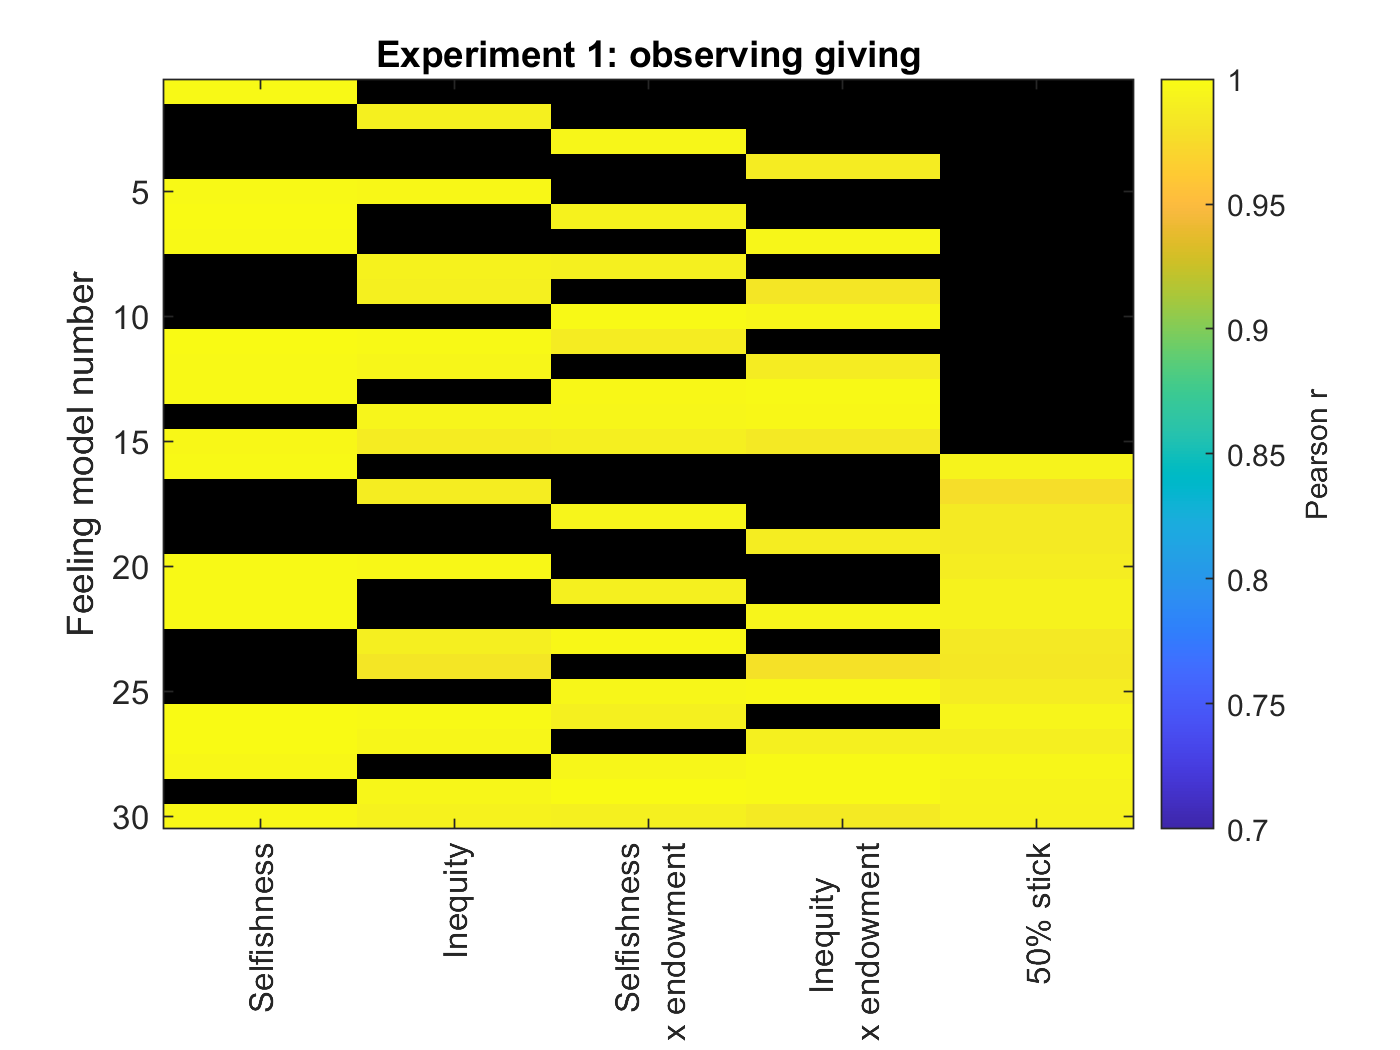

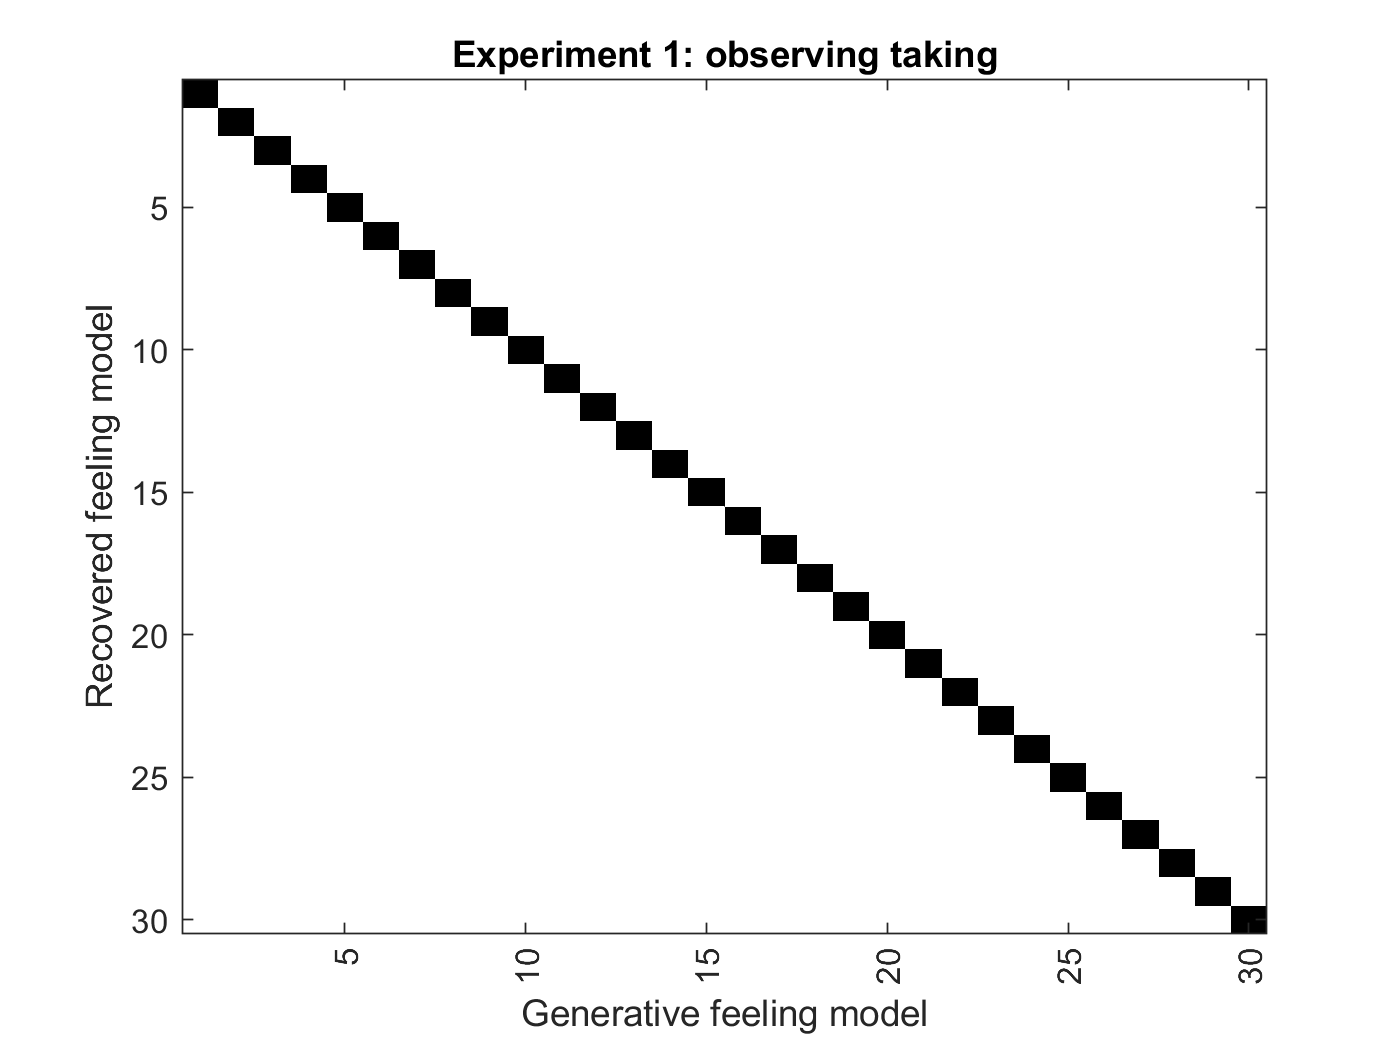

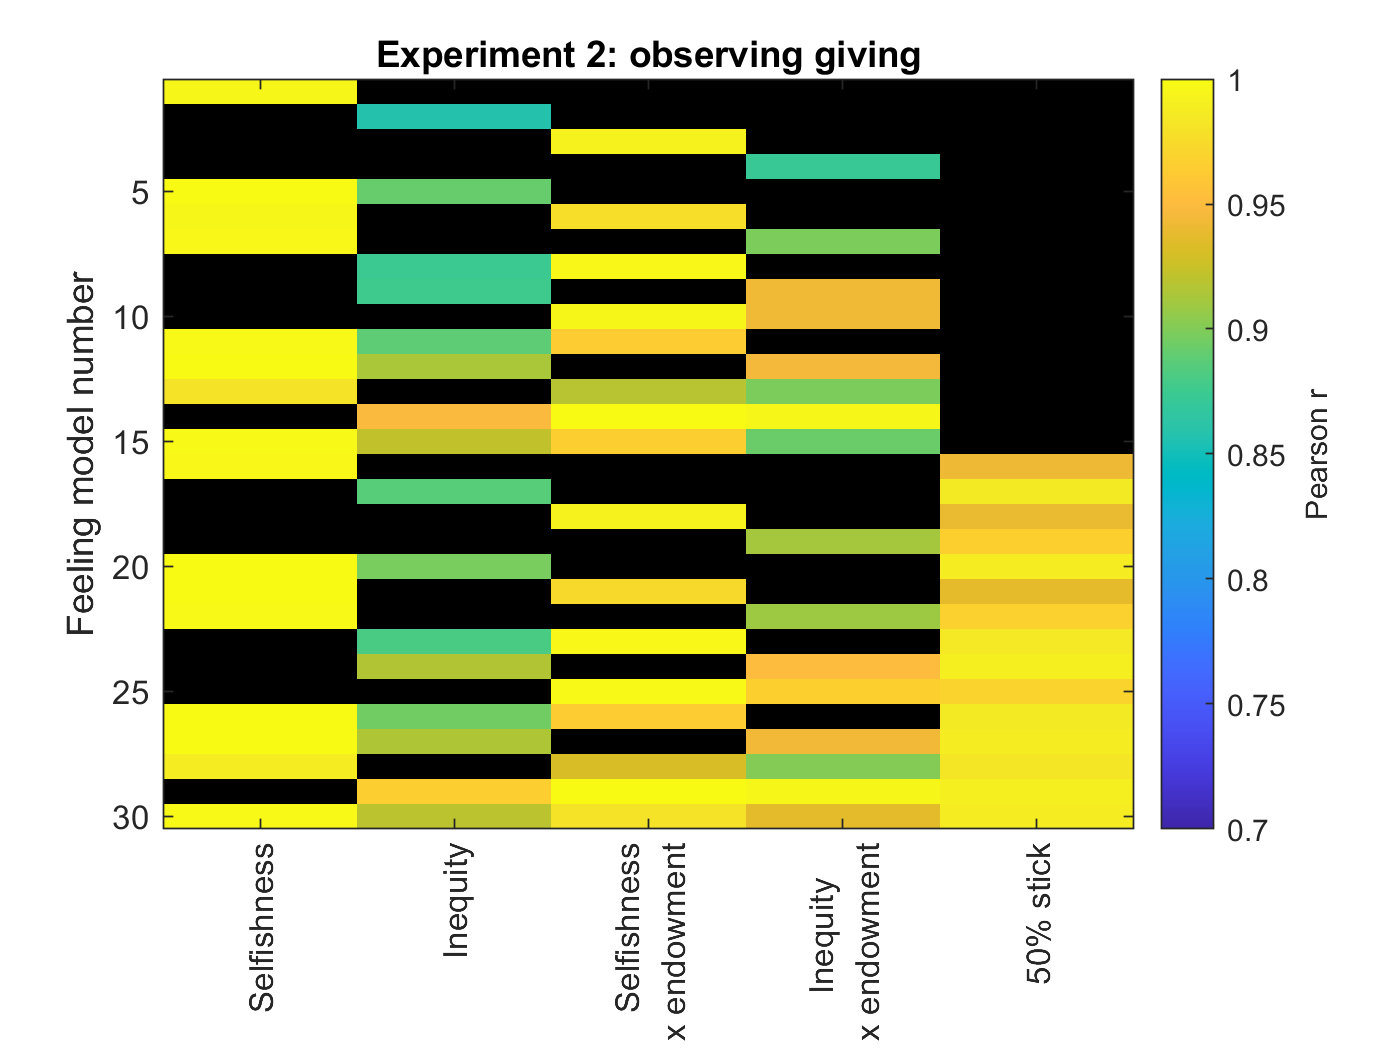

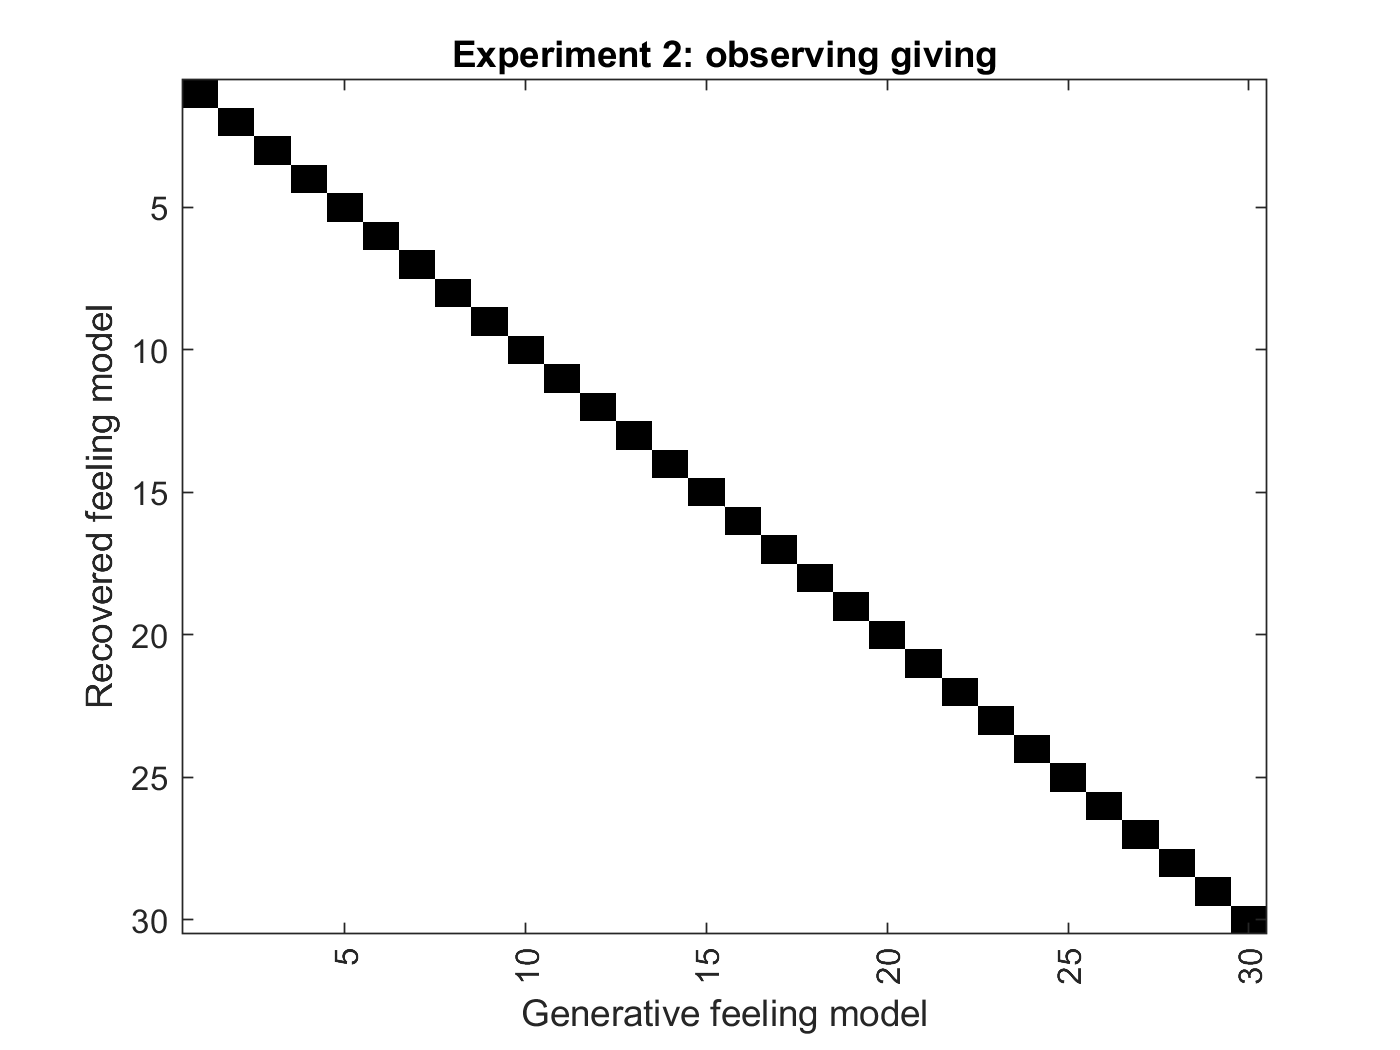

    % get the BIC sum
    matSumBic = squeeze(nansum(BICR{iExp},1));

    % intialise the best model matrix
    matBest = zeros(nModel,nModel);
    for iModel=1:nModel
        tmp = min(matSumBic(iModel,:));
        idx = find(matSumBic(iModel,:)==tmp);
        tmp2 = matSumBic(iModel,:); tmp2(idx) = [];
        tmp3 = min(tmp2);
        if abs(tmp3-tmp)>30 % 1 if the model is best (delta BIC>30) or 0.5 if
            matBest(iModel,idx) = 1;
        elseif abs(tmp3-tmp)>3
            matBest(iModel,idx) = 0.5; % 0.5 if the model is best (delta BIC>3 but <30)
        else
            matBest(iModel,idx) = 0; % if not recovered
        end
        matComp(iModel,:) = matSumBic(iModel,:)-tmp;
    end
    % plot the model recovery matrix
    %     figure(101);
    figure
    %     subplot(2,2,iExp);
    imagesc(matBest);colormap(map2)
    if (iExp)==1
        title('Experiment 1: observing taking')
        ylabel('Recovered feeling model')
        xlabel('Generative feeling model')
    elseif (iExp)==2
        title('Experiment 2: observing giving')
        ylabel('Recovered feeling model')
        xlabel('Generative feeling model')
    elseif (iExp)==3
        title('Experiment 1: observing taking')
        ylabel('Recovered punishment model')
        xlabel('Generative punishment model')
    elseif (iExp)==4
        title('Experiment 2: observing taking')
        ylabel('Recovered punishment model')
        xlabel('Generative punishment model')
    end
    set(gca,'XTick',5:5:30,'XTickLabelRotation',90)
    % fill the table
    TModelRecovery{iExp} = array2table(matSumBic);
end

**Fig 5.** **Modelling observers’** **feelings as a function of observed selfishness and inequality. **

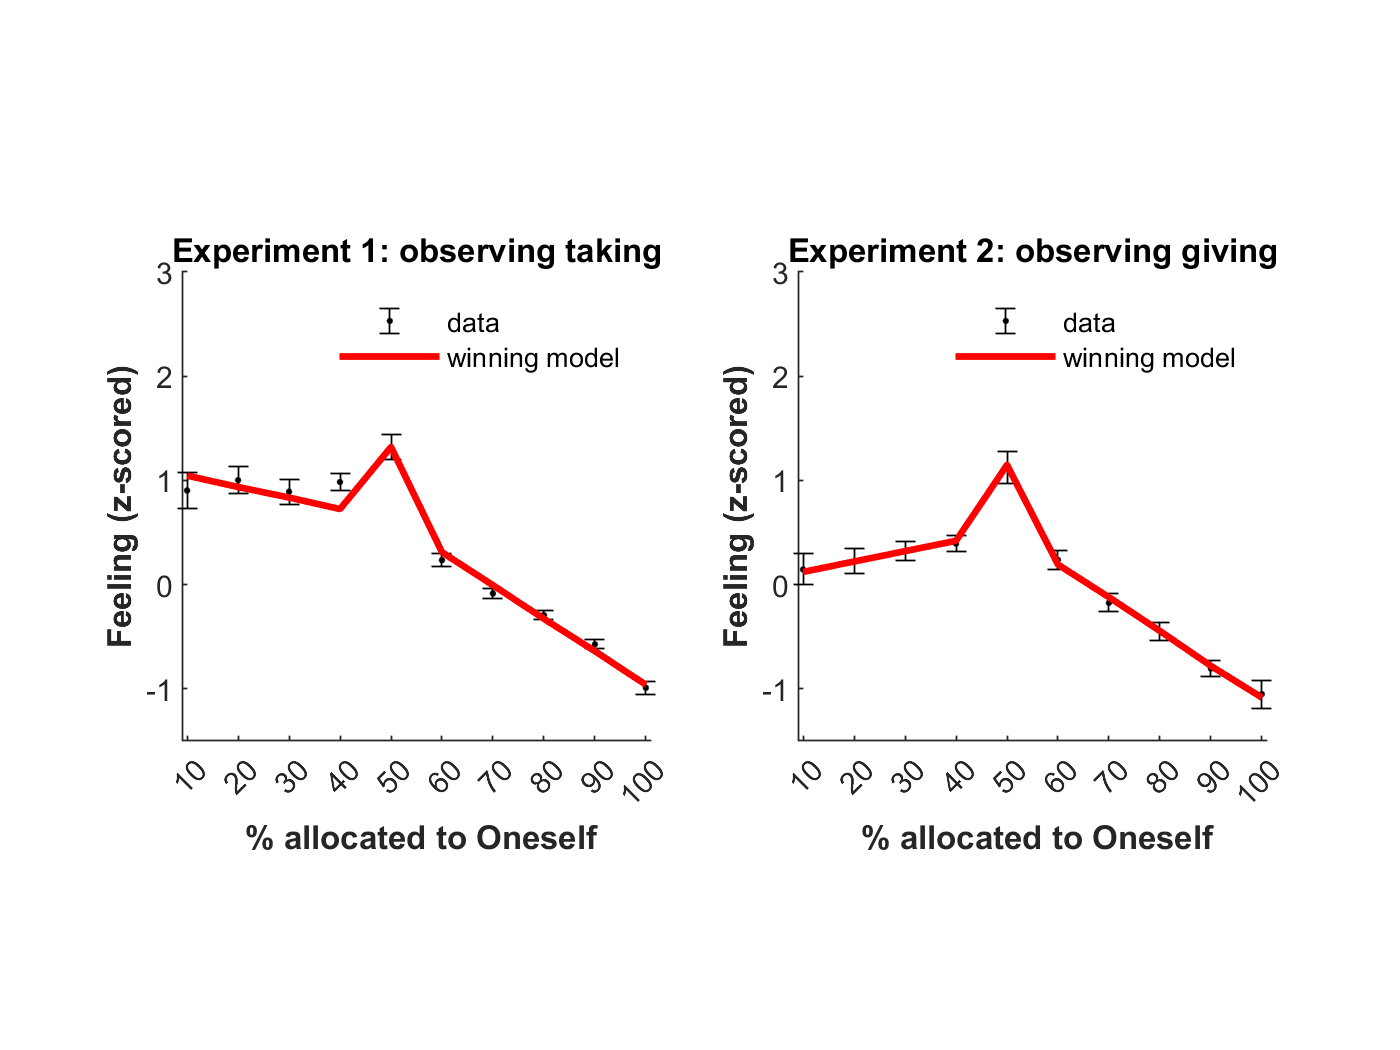

for iExp=[1 2]
    % get the correct length
    if iExp<2
        sublength = (length(unique(FeelingsData1.ID)));
    else
        sublength = (length(unique(FeelingsData2.ID)));
    end
    % intialise a few variables
    yM = [];ySD=[];ypredM=[];ypredSD=[];X=[];lUniqueSelf=[];
    % loop through each participants
    for i=1:sublength        
        if iExp==1
            X = double(FeelingsData1(FeelingsData1.ID==i,[6,8,7,5]));
        elseif iExp==2
            X = double(FeelingsData2(FeelingsData2.ID==i,[6,8,7,5]));
        end
        figure(201);subplot(1,2,iExp);hold on;
        % get the unique shared amounts
        lUniqueSelf = unique(X(:,1));
        % erase the nan
        lUniqueSelf(isnan(lUniqueSelf))=[];
        %loop through each split and get bins
        for iSelf=1:length(lUniqueSelf)
            idx =  X(:,1)==lUniqueSelf(iSelf);
            yM(i,iSelf)  = mean(X(idx,4));
            ySD(i,iSelf) = std(X(idx,4));
            ypredM(i,iSelf) = mean(predG{iExp,i,26}(idx));
            ypredSD(i,iSelf) = std(predG{iExp,i,26}(idx))./sqrt(sublength);
        end
    end
    % plotting
    errorbar(lUniqueSelf,nanmean(yM,1),nanstd(yM,1)./sqrt(sublength),'.k')    
    plot(lUniqueSelf,nanmean(ypredM,1),'r','LineWidth',2)
    xlabel('\bf{ % allocated to Oneself}')
    ylabel('\bf{Feeling} (z-scored)')
    legend({'data','winning model'})
    legend boxoff
    xlim([9 101])
    axis square
    if iExp==1
        title('Experiment 1: observing taking')
    elseif iExp==2
        title('Experiment 2: observing giving')
    end
    ylim([-1.5 3])
    set(gca,'XTick',10:10:100)
end

Get the table

for iExp=1:4
    for iModel=1:nModel
        dataStats{iExp,iModel}.param(:,1) = [nanmean(matParamRecGenMu{iExp,iModel})];
        dataStats{iExp,iModel}.param(:,2) = [nanstd(matParamRecGenMu{iExp,iModel})./sqrt(size(matParamRecGenMu{iExp,iModel},1))];
        dataStats{iExp,iModel}.param(:,3) = dataStats{iExp,iModel}.param(:,1) + dataStats{iExp,iModel}.param(:,2).*[-norminv((0.95+1)/2)];
        dataStats{iExp,iModel}.param(:,4) = dataStats{iExp,iModel}.param(:,1) + dataStats{iExp,iModel}.param(:,2).*[norminv((0.95+1)/2)];
        [h p dev stats2] = ttest(matParamRecGenMu{iExp,iModel});
        dataStats{iExp,iModel}.param(:,5) = stats2.df;
        dataStats{iExp,iModel}.param(:,6) = stats2.tstat;
        dataStats{iExp,iModel}.param(:,7) = p;        
    end
end

## **Observer’s decisions to punish are a function of both selfishness aversion and inequality aversion**

### **ANOVA**

#### Experiment 1

AllPunishmentData1 = [PunishmentData1; FeelingsData1(:,[1:3 11:12 6:8 13:14])];
sublength = (length(unique(FeelingsData1.ID)));

 Punishment as a binary variable

[meanpunExp1Tmp,grpsPunExp1] = grpstats(AllPunishmentData1.PunBinary,{AllPunishmentData1.Allocator,AllPunishmentData1.ID},{'mean','gname'});
grpsPunExp1=cellfun(@str2double,grpsPunExp1);
for i = [2 0 1]
    meanpunExp1(1:sublength,i+1) = meanpunExp1Tmp((grpsPunExp1(:,1))==i);
end
mean(meanpunExp1)

ans =     0.3600    0.3281    0.9773


std(meanpunExp1)

ans =     0.3788    0.3885    0.0463


grpsPunExp1(:,1) = grpsPunExp1(:,1)+1;
rmANOVAs.punishmentBinary1 = [meanpunExp1Tmp grpsPunExp1];
RMAOV1(rmANOVAs.punishmentBinary1)

The number of IV levels are: 3

The number of subjects are:32

Repeated Measures One-Way Analysis of Variance Table.
---------------------------------------------------------------------------
SOV                  SS          df           MS             F        P
---------------------------------------------------------------------------
Subjects            6.004        31          0.194[        3.766   0.0000]

IV                  8.569         2          4.285        83.299   0.0000

Error               3.189        62          0.051

Total              17.763        95

---------------------------------------------------------------------------
If the P result is smaller than 0.05
the Ho tested results statistically significant. Otherwise, it is not significative.
[Generally speaking, no Mean Square is computed for the variable "subjects" since it is assumed
that subjects differ from one another thus making a significance test of "subjects" superfluous.
However, for all the interes

rmANOVAs.partialeta.punishmentBinary1 = 8.569 / (8.569 + 3.189);

[h,p,ci,stats] = ttest(meanpunExp1(:,3),meanpunExp1(:,1))

h = 1

p = 1.5183e-10

ci =     0.4827
    0.7517


stats = struct with fields:
    tstat: 9.3599
       df: 31
       sd: 0.3730


CohensD.Punishment1.Frequency.SelfishGenerous = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanpunExp1(:,3),meanpunExp1(:,2))

h = 1

p = 7.6039e-11

ci =     0.5118
    0.7864


stats = struct with fields:
    tstat: 9.6417
       df: 31
       sd: 0.3808


CohensD.Punishment1.Frequency.SelfishEqual = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanpunExp1(:,1),meanpunExp1(:,2))

h = 0

p = 0.2570

ci =    -0.0244
    0.0882


stats = struct with fields:
    tstat: 1.1549
       df: 31
       sd: 0.1563


CohensD.Punishment1.Frequency.GenerousEqual = stats.tstat/sqrt(sublength);

Punishment amount

[meanpunAmExp1Tmp,grpsPunAmExp1] = grpstats(AllPunishmentData1.Punishment,{AllPunishmentData1.Allocator,AllPunishmentData1.ID},{'mean','gname'});
grpsPunAmExp1=cellfun(@str2double,grpsPunAmExp1);
for i = [2 0 1]
    meanpunAmExp1(1:sublength,i+1) = meanpunAmExp1Tmp((grpsPunAmExp1(:,1))==i);
end
mean(meanpunAmExp1)

ans =     0.1465    0.1381    0.6529


std(meanpunAmExp1)

ans =     0.1960    0.2118    0.1338


grpsPunAmExp1(:,1) = grpsPunAmExp1(:,1)+1;
rmANOVAs.punishment1 = [meanpunAmExp1Tmp grpsPunAmExp1];
RMAOV1(rmANOVAs.punishment1);

The number of IV levels are: 3

The number of subjects are:32

Repeated Measures One-Way Analysis of Variance Table.
---------------------------------------------------------------------------
SOV                  SS          df           MS             F        P
---------------------------------------------------------------------------
Subjects            2.098        31          0.068[        4.036   0.0000]

IV                  5.563         2          2.782       165.920   0.0000

Error               1.039        62          0.017

Total               8.701        95

---------------------------------------------------------------------------
If the P result is smaller than 0.05
the Ho tested results statistically significant. Otherwise, it is not significative.
[Generally speaking, no Mean Square is computed for the variable "subjects" since it is assumed
that subjects differ from one another thus making a significance test of "subjects" superfluous.
However, for all the interes

rmANOVAs.partialeta.punishment1 = 5.563 / (5.563 + 1.039);

[h,p,ci,stats] = ttest(meanpunAmExp1(:,3),meanpunAmExp1(:,1))

h = 1

p = 7.8826e-15

ci =     0.4319
    0.5809


stats = struct with fields:
    tstat: 13.8586
       df: 31
       sd: 0.2067


CohensD.Punishment1.Amount.SelfishGenerous = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanpunAmExp1(:,3),meanpunAmExp1(:,2))

h = 1

p = 8.6597e-15

ci =     0.4388
    0.5909


stats = struct with fields:
    tstat: 13.8104
       df: 31
       sd: 0.2109


CohensD.Punishment1.Amount.SelfishEqual = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanpunAmExp1(:,1),meanpunAmExp1(:,2))

h = 0

p = 0.6823

ci =    -0.0333
    0.0502


stats = struct with fields:
    tstat: 0.4132
       df: 31
       sd: 0.1157


CohensD.Punishment1.Amount.GenerousEqual = stats.tstat/sqrt(sublength);

#### Experiment 2

Punishment as a binary variable

sublength = (length(unique(FeelingsData2.ID)));
[meanpunExp2Tmp,grpsPunExp2] = grpstats(PunishmentData2.PunBinary,{PunishmentData2.Allocator,PunishmentData2.ID},{'mean','gname'});
grpsPunExp2=cellfun(@str2double,grpsPunExp2);
for i = [2 0 1]
    meanpunExp2(1:sublength,i+1) = meanpunExp2Tmp((grpsPunExp2(:,1))==i);
end
mean(meanpunExp2)

ans =     0.2167    0.1333    0.8743


std(meanpunExp2)

ans =     0.3117    0.2271    0.1386


grpsPunExp2(:,1) = grpsPunExp2(:,1)+1;
rmANOVAs.punishmentBinary2 = [meanpunExp2Tmp grpsPunExp2];
RMAOV1(rmANOVAs.punishmentBinary2)

The number of IV levels are: 3

The number of subjects are:35

Repeated Measures One-Way Analysis of Variance Table.
---------------------------------------------------------------------------
SOV                  SS          df           MS             F        P
---------------------------------------------------------------------------
Subjects            3.391        34          0.100[        2.925   0.0001]

IV                 11.532         2          5.766       169.107   0.0000

Error               2.318        68          0.034

Total              17.241       104

---------------------------------------------------------------------------
If the P result is smaller than 0.05
the Ho tested results statistically significant. Otherwise, it is not significative.
[Generally speaking, no Mean Square is computed for the variable "subjects" since it is assumed
that subjects differ from one another thus making a significance test of "subjects" superfluous.
However, for all the interes

rmANOVAs.partialeta.punishmentBinary2 = 11.532 / (11.532 + 2.318);

[h,p,ci,stats] = ttest(meanpunExp2(:,3),meanpunExp2(:,1));
CohensD.Punishment2.Frequency.SelfishGenerous = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanpunExp2(:,3),meanpunExp2(:,2));
CohensD.Punishment2.Frequency.SelfishEqual = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanpunExp2(:,1),meanpunExp2(:,2));
CohensD.Punishment2.Frequency.GenerousEqual = stats.tstat/sqrt(sublength);

Punishment amount

[meanpunAmExp2Tmp,grpsPunAmExp2] = grpstats(PunishmentData2.Punishment,{PunishmentData2.Allocator,PunishmentData2.ID},{'mean','gname'});
grpsPunAmExp2=cellfun(@str2double,grpsPunAmExp2);
for i = [2 0 1]
    meanpunAmExp2(1:sublength,i+1) = meanpunAmExp2Tmp((grpsPunAmExp2(:,1))==i);
end
grpsPunAmExp2(:,1) = grpsPunAmExp2(:,1)+1;
rmANOVAs.punishment2 = [meanpunAmExp2Tmp grpsPunAmExp2];
RMAOV1(rmANOVAs.punishment2)

The number of IV levels are: 3

The number of subjects are:35

Repeated Measures One-Way Analysis of Variance Table.
---------------------------------------------------------------------------
SOV                  SS          df           MS             F        P
---------------------------------------------------------------------------
Subjects            1.094        34          0.032[        1.582   0.0544]

IV                  3.691         2          1.846        90.732   0.0000

Error               1.383        68          0.020

Total               6.169       104

---------------------------------------------------------------------------
If the P result is smaller than 0.05
the Ho tested results statistically significant. Otherwise, it is not significative.
[Generally speaking, no Mean Square is computed for the variable "subjects" since it is assumed
that subjects differ from one another thus making a significance test of "subjects" superfluous.
However, for all the interes

rmANOVAs.partialeta.punishment2 = 3.691 / (3.691 + 1.383);

[h,p,ci,stats] = ttest(meanpunAmExp2(:,3),meanpunAmExp2(:,1));
CohensD.Punishment2.Amount.SelfishGenerous = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanpunAmExp2(:,3),meanpunAmExp2(:,2));
CohensD.Punishment2.Amount.SelfishEqual = stats.tstat/sqrt(sublength);
[h,p,ci,stats] = ttest(meanpunAmExp2(:,1),meanpunAmExp2(:,2));
CohensD.Punishment2.Amount.GenerousEqual = stats.tstat/sqrt(sublength);

**Fig 6. Observers’ Punishment. **

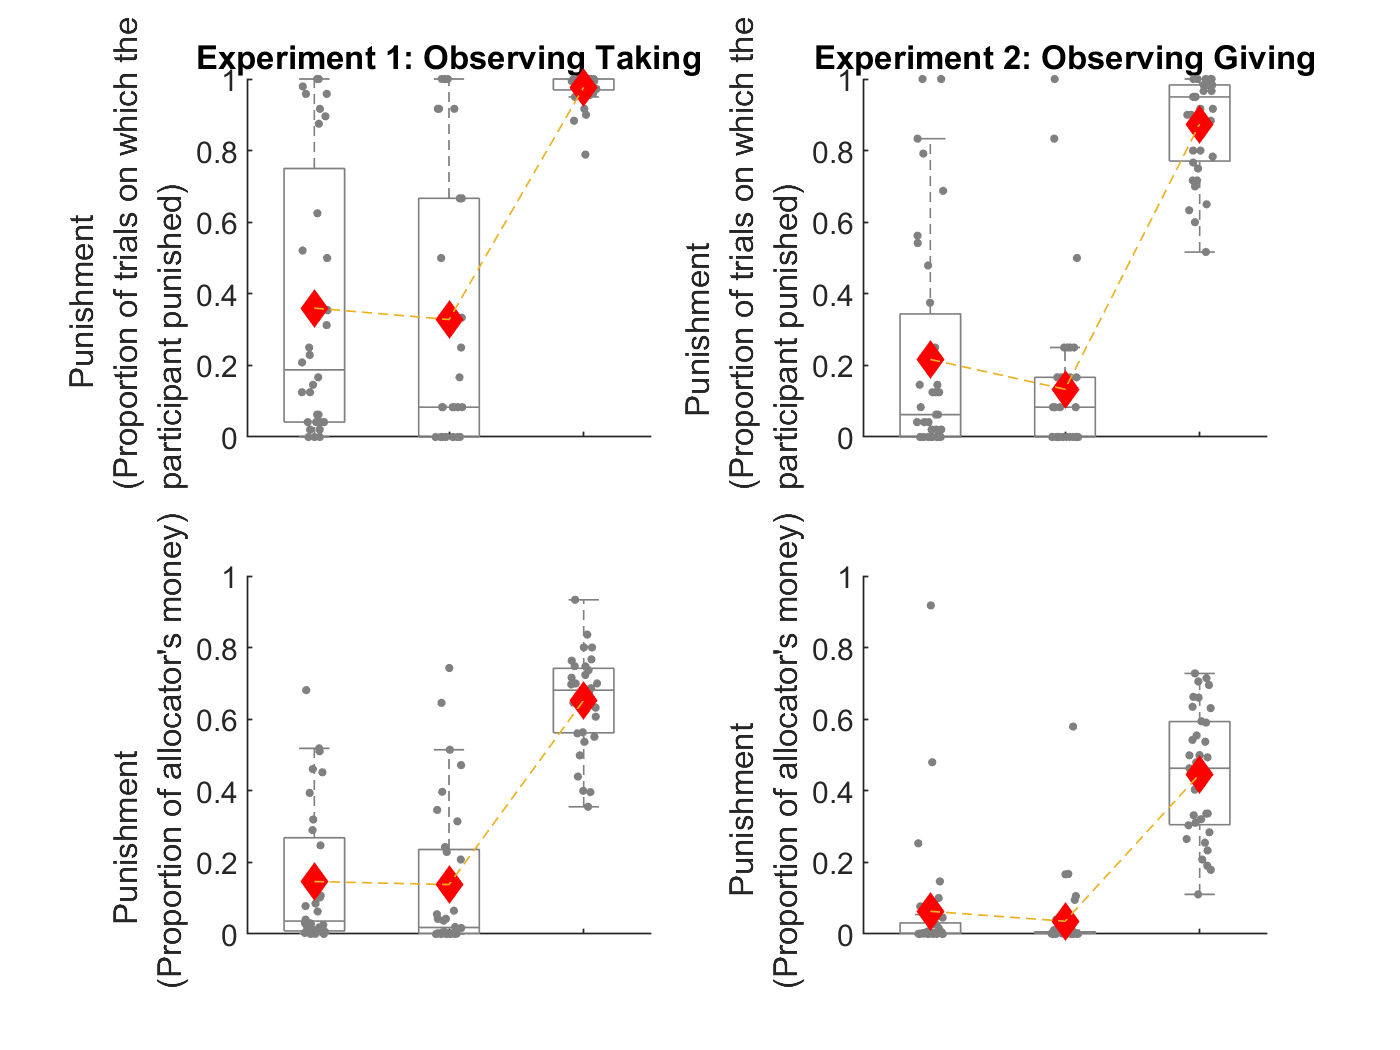

figure
subplot(2,2,1)
boxplot(meanpunExp1,'Colors',[0.5 0.5 0.5],'Symbol','')
sz = 4;
hold on
scatter(grpsPunExp1(:,1)-.1+rand(length(grpsPunExp1(:,1)),1)/5,meanpunExp1Tmp,sz,'filled','MarkerEdgeColor',[.5 .5 .5],...
              'MarkerFaceColor',[.5 .5 .5])
ax = gca;
%ax.XLim = [0 4];
ax.YLim = [0 1];
xticks([1,2,3]);
xticklabels({' ',' ',' '})
set(gca,'box','off');
set(gcf,'color','w');
hold on
plot(1:3,mean(meanpunExp1), 'dr','MarkerSize',8,'MarkerFaceColor','r')
plot(1:3,mean(meanpunExp1),'--')
hold off
title('Experiment 1: Observing Taking')
ylabel('            Punishment\newline (Proportion of trials on which the\newline participant punished)')

subplot(2,2,3)
boxplot(meanpunAmExp1,'Colors',[0.5 0.5 0.5],'Symbol','')
sz = 4;
hold on
scatter(grpsPunAmExp1(:,1)-.1+rand(length(grpsPunAmExp1(:,1)),1)/5,meanpunAmExp1Tmp,sz,'filled','MarkerEdgeColor',[.5 .5 .5],...
              'MarkerFaceColor',[.5 .5 .5])
ax = gca;
%ax.XLim = [0 4];
ax.YLim = [0 1];
xticks([1,2,3]);
xticklabels({' ',' ',' '})
set(gca,'box','off');
set(gcf,'color','w');
hold on
plot(1:3,mean(meanpunAmExp1), 'dr','MarkerSize',8,'MarkerFaceColor','r')
plot(1:3,mean(meanpunAmExp1),'--')
hold off
ylabel('        Punishment\newline (Proportion of allocator''s money)')

subplot(2,2,2)
boxplot(meanpunExp2,'Colors',[0.5 0.5 0.5],'Symbol','')
sz = 4;
hold on
scatter(grpsPunExp2(:,1)-.1+rand(length(grpsPunExp2(:,1)),1)/5,meanpunExp2Tmp,sz,'filled','MarkerEdgeColor',[.5 .5 .5],...
              'MarkerFaceColor',[.5 .5 .5])
ax = gca;
%ax.XLim = [0 4];
ax.YLim = [0 1];
xticks([1,2,3]);
xticklabels({' ',' ',' '})
set(gca,'box','off');
set(gcf,'color','w');
hold on
plot(1:3,mean(meanpunExp2), 'dr','MarkerSize',8,'MarkerFaceColor','r')
plot(1:3,mean(meanpunExp2),'--')
hold off
ylabel('         Punishment\newline (Proportion of trials on which the\newline participant punished)')
title('Experiment 2: Observing Giving')

subplot(2,2,4)
boxplot(meanpunAmExp2,'Colors',[0.5 0.5 0.5],'Symbol','')
sz = 4;
hold on
scatter(grpsPunAmExp2(:,1)-.1+rand(length(grpsPunAmExp2(:,1)),1)/5,meanpunAmExp2Tmp,sz,'filled','MarkerEdgeColor',[.5 .5 .5],...
              'MarkerFaceColor',[.5 .5 .5])
ax = gca;
%ax.XLim = [0 4];
ax.YLim = [0 1];
xticks([1,2,3]);
xticklabels({' ',' ',' '})
set(gca,'box','off');
set(gcf,'color','w');
hold on
plot(1:3,mean(meanpunAmExp2), 'dr','MarkerSize',8,'MarkerFaceColor','r')
plot(1:3,mean(meanpunAmExp2),'--')
ylabel('           Punishment\newline (Proportion of allocator''s money)')
hold off

**Fig 7 A,B & C.**  **Punishment Model**. 

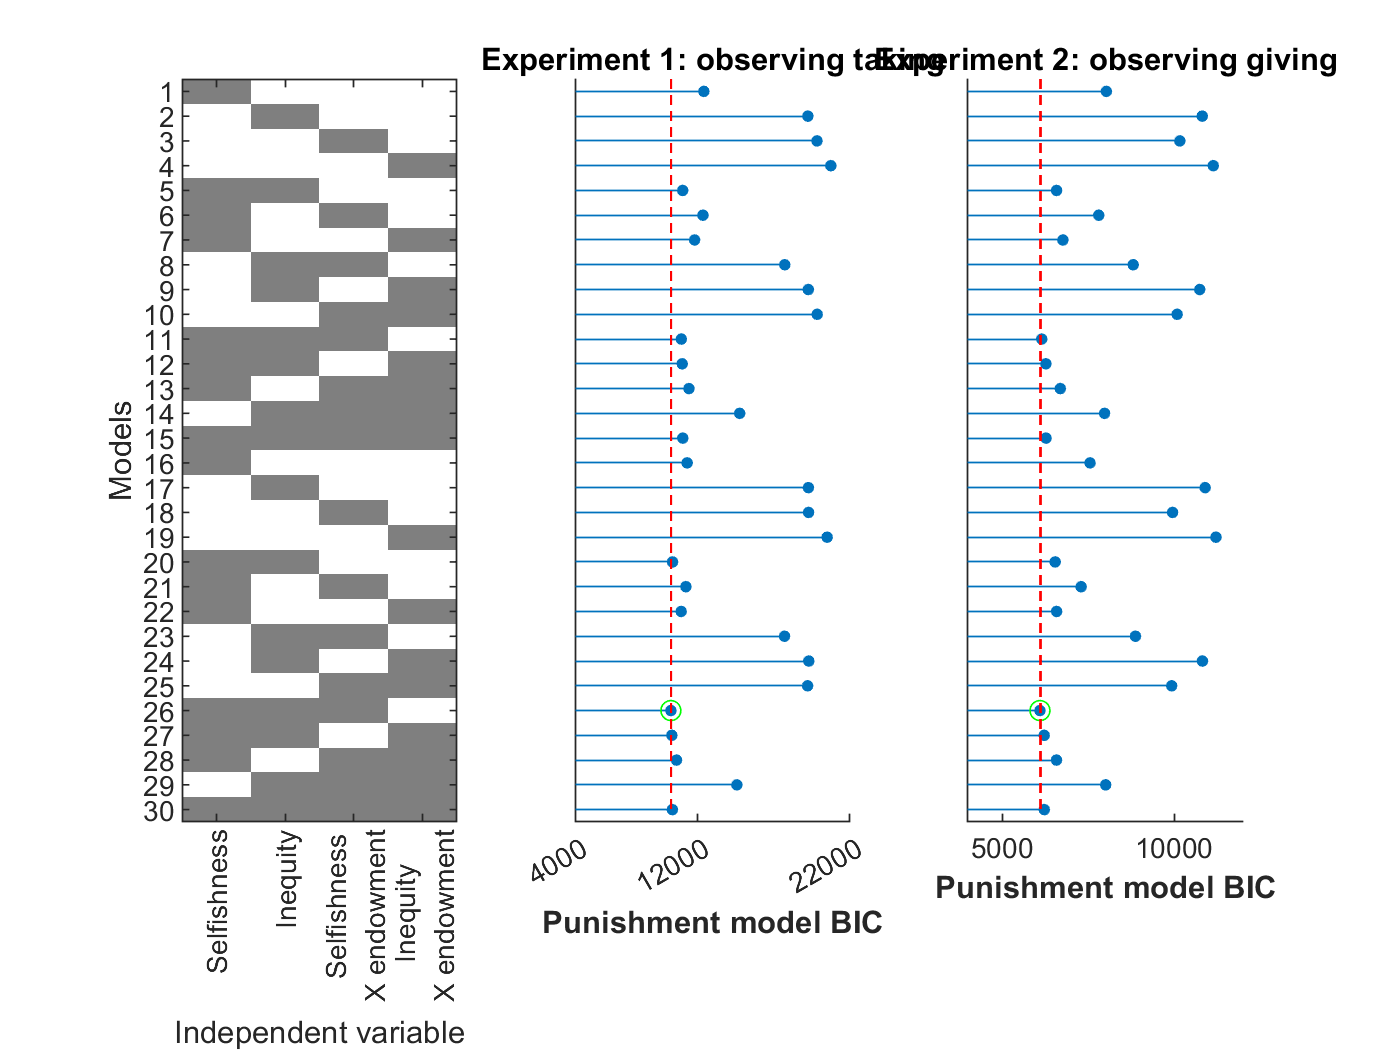

figure;
c=0;
for iExp=[0 3 4]
    if c==0
        subplot(1,3,1)
        imagesc(matParam(:,1:(end-1)));
        colormap(map)
        c=c+1;
        xlabel('Independent variable')
        ylabel('Models')
        set(gca,'XTick',1:5,'YTick',1:size(matParam,1),'YTickLabel',num2str([1:1:size(matParam,1)]'),'XTickLabel',{'Selfishness','Inequity','    Selfishness\newline X endowment','      Inequity\newline X endowment','50% stick'},...
            'XTickLabelRotation',90)
    else
        c=c+1;
        BICall=zeros(1,nModel);
        BICall = BICall + nansum(BIC{iExp},1);
        subplot(1,3,c);hold on;
        bestModel(iExp) = find(BICall==min(BICall));
        stem(BICall,'filled','MarkerSize',3);        
        plot(bestModel(iExp),min(BICall),'go')
        plot([0 nModel],[min(BICall) min(BICall)],'r--')
        plot([0 nModel],[min(BICall)+30 min(BICall)+30],'r--')
        ylabel('\bf{Punishment} model BIC')
        if iExp==3
            title('Experiment 1: observing taking')
             ylim([4000 22000])
             set(gca,'XTick',[],'XTickLabelRotation',0,'XTickLabel','','YTick',[4000 12000 22000],'YTickLabel',num2str([4000 12000 22000]'))
        elseif iExp==4
            title('Experiment 2: observing giving')
             ylim([4000 12000])
             set(gca,'XTick',[],'XTickLabelRotation',0,'XTickLabel','')
        end       
        xlim([0.5 nModel+0.5])
        set(gca,'view',[90 -90],'XDir','reverse')
    end
end

Get the corresponding tables

disp('Feeling,Experiment 1')

Feeling,Experiment 1


disp(modelComparisonTable{1})

    modelNumber    parameterNumber      r2        bic      rank
    ___________    _______________    _______    ______    ____

         1                2           0.51387      7362     16 
         2                2           0.28795      9623     24 
         3                2           0.23017    9993.6     28 
         4                2           0.18253     10230     30 
         5                3           0.61257    6805.7     12 
         6                3             0.535      7306     15 
         7                3           0.58604    6999.3     14 
         8                3            0.4147    8986.2     20 
         9                3           0.30531    9657.6     26 
        10                3            0.3022    9750.4     27 
        11                4           0.63168    6708.6      

disp('Feeling,Experiment 2')

Feeling,Experiment 2


disp(modelComparisonTable{2})

    modelNumber    parameterNumber      r2        bic      rank
    ___________    _______________    _______    ______    ____

         1                2           0.43042    8687.3     20 
         2                2           0.32615    9914.1     26 
         3                2           0.22297     10676     29 
         4                2           0.20173     10841     30 
         5                3           0.67357    6911.8     11 
         6                3           0.44755    8677.8     19 
         7                3           0.58806    7720.2     15 
         8                3           0.49779    8924.3     21 
         9                3           0.34261    9961.9     28 
        10                3           0.38744    9919.4     27 
        11                4           0.69132    6822.8      

**Fig 7 D-G Parameter recovery analysis & Model recovery analysis. **

map2 = [1 1 1
    0 0 0];
r=[];p=[];
for iExp=3:4
    % initialiase tables
    tableParamRecBeta{iExp} = nan(nModel,14);
    matParamRecR{iExp} = nan(nModel,7);
    matParamRecRP{iExp} = nan(nModel,7);  
 

**D & E: Parameter recovery**

    if sum(iExp==[1,3])==1
        sublength = (length(unique(FeelingsData1.ID)));
    else
        sublength = (length(unique(FeelingsData2.ID)));
    end     
    for iModel=1:nModel
        c=0;
        for i=1:sublength
            matParamRecGen{iExp,iModel}(i,:) = estimates{iExp,i,iModel}.muPhi;
            matParamRecEst{iExp,iModel}(i,:) =  estimatesR{iExp,i,iModel,iModel}.muPhi;
        end
    end
    matB = nan(nModel,nReg,2);
    matP = nan(nModel,nReg,2);
    for iModel=1:nModel
        idxParam = find(matParam(iModel,:));
        for iParam=1:length(matParam(iModel,:)) 
            if matParam(iModel,iParam)==1
            % add one to the matParam index to ignore the constant
             [r{iExp,iModel}(iParam),p{iExp,iModel}(iParam)] = corr(matParamRecGen{iExp,iModel}(:,iParam+1),(matParamRecEst{iExp,iModel}(:,iParam+1)));
            [b,dev,stats] = glmfit(matParamRecGen{iExp,iModel}(:,iParam+1),(matParamRecEst{iExp,iModel}(:,iParam+1)));
            matB(iModel,(iParam),:) = b;
            matP(iModel,(iParam),:) = stats.p;
            matR(iModel,(iParam),:) = r{iExp,iModel}(iParam) ;
            matRP(iModel,(iParam),:) = p{iExp,iModel}(iParam) ;
            end
        end
        % create table
        idxParam = find(matParam(iModel,:));
        for iParam=1:sum(matParam(iModel,:))
            tableParamRecBeta{iExp}(iModel,(idxParam(iParam)*2-1):(idxParam(iParam)*2)) = matB(iModel,idxParam(iParam),:);
            matParamRecR{iExp}(iModel,(idxParam(iParam))) = matR(iModel,idxParam(iParam),:);
            matParamRecRP{iExp}(iModel,(idxParam(iParam))) = matRP(iModel,idxParam(iParam),:);
        end
    end
    figure
%     figure(102);
%     subplot(2,2,(iExp));
    imAlpha=ones(size(matParamRecR{iExp}(:,1:5)));
    imAlpha(isnan(matParamRecR{iExp}(:,1:5)))=0;
    imagesc(matParamRecR{iExp}(:,1:5),'AlphaData',imAlpha);
    c=colorbar;colormap(parula)
    c.Label.String = 'Pearson r';
    set(c, 'ylim', [0.7 1])
    caxis([0.7 1])
    set(gca,'color',0*[1 1 1]);
    ylabel('Model number')
    set(gca,'XTick',1:5,'XTickLabel',{'Selfishness','Inequity','    Selfishness\newline x endowment','      Inequity\newline x endowment','50% stick'},...
        'XTickLabelRotation',90)
    if (iExp)==1
        title('Experiment 1: observing giving')
        ylabel('Feeling model number')        
    elseif (iExp)==2
        title('Experiment 2: observing giving')
        ylabel('Feeling model number')  
    elseif (iExp)==3
        title('Experiment 1: observing taking')
        ylabel('Punishment model number')  
    elseif (iExp)==4
        title('Experiment 2: observing taking')
        ylabel('Punishment model number')       
    end
%     %% bonus: uncomment for the p-value matrices

%     figure;subplot(2,2,(iExp));
%     imAlpha=ones(size(matParamRecRP{iExp}(:,1:5)));
%     imAlpha(isnan(matParamRecRP{iExp}(:,1:5)))=-99;
%     imagesc(matParamRecRP{iExp}(:,1:5),'AlphaData',imAlpha);
%     c=colorbar;colormap(parula)
%     c.Label.String = 'p-value';
%     set(c, 'ylim', [0 0.1])
%     caxis([0 0.1])
%     set(gca,'color',0*[1 1 1]);
%     ylabel('Model number')
%     set(gca,'XTick',1:5,'XTickLabel',{'Selfishness','Inequity','    Selfishness\newline x endowment','      Inequity\newline x endowment','50% stick'},...
%         'XTickLabelRotation',90)
%     if (iExp)==1
%         title('Experiment 1: observing giving')
%         ylabel('Feeling model number')
%     elseif (iExp)==2
%         title('Experiment 2: observing giving')
%         ylabel('Feeling model number')
%     elseif (iExp)==3
%         title('Experiment 1: observing taking')
%         ylabel('Punishment model number')
%     elseif (iExp)==4
%         title('Experiment 2: observing taking')
%         ylabel('Punishment model number')
%     end


**F & G: Model recovery**

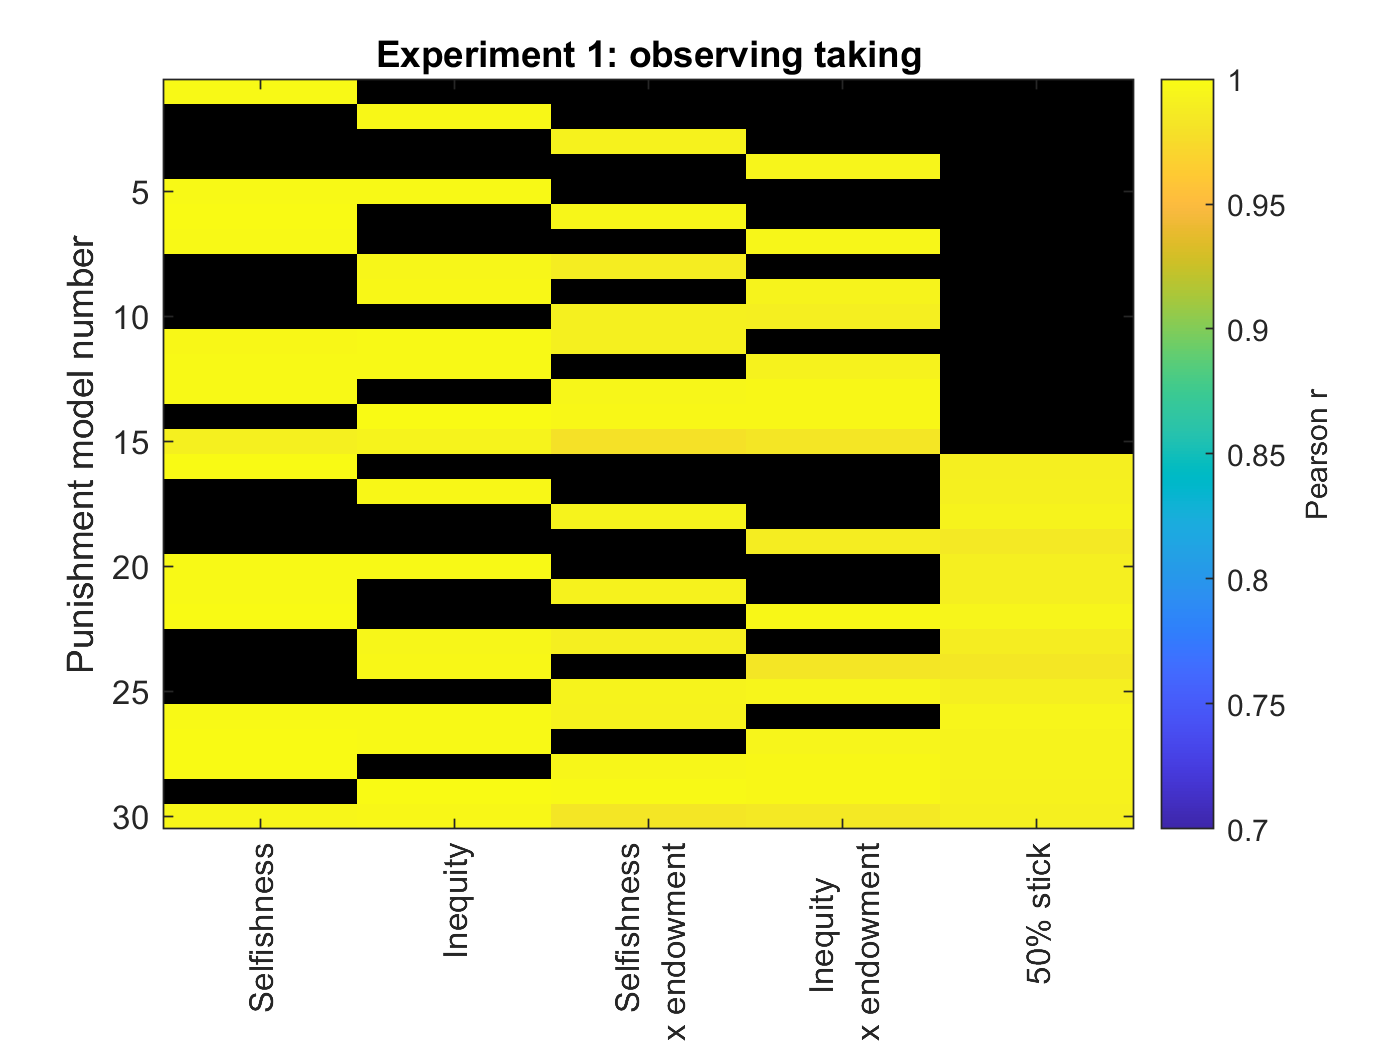

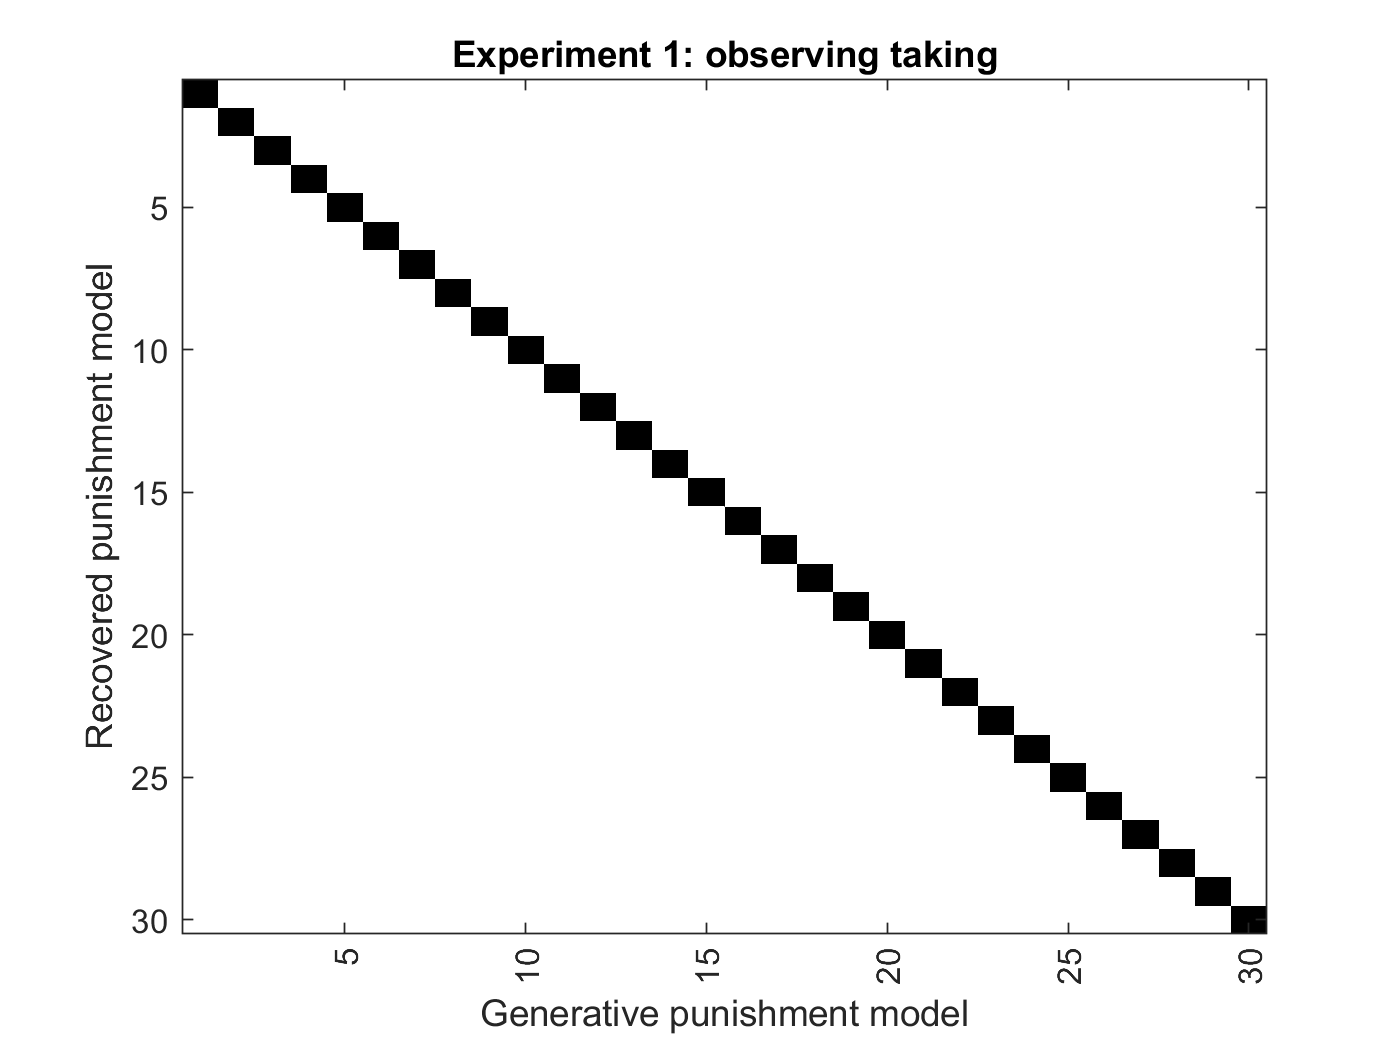

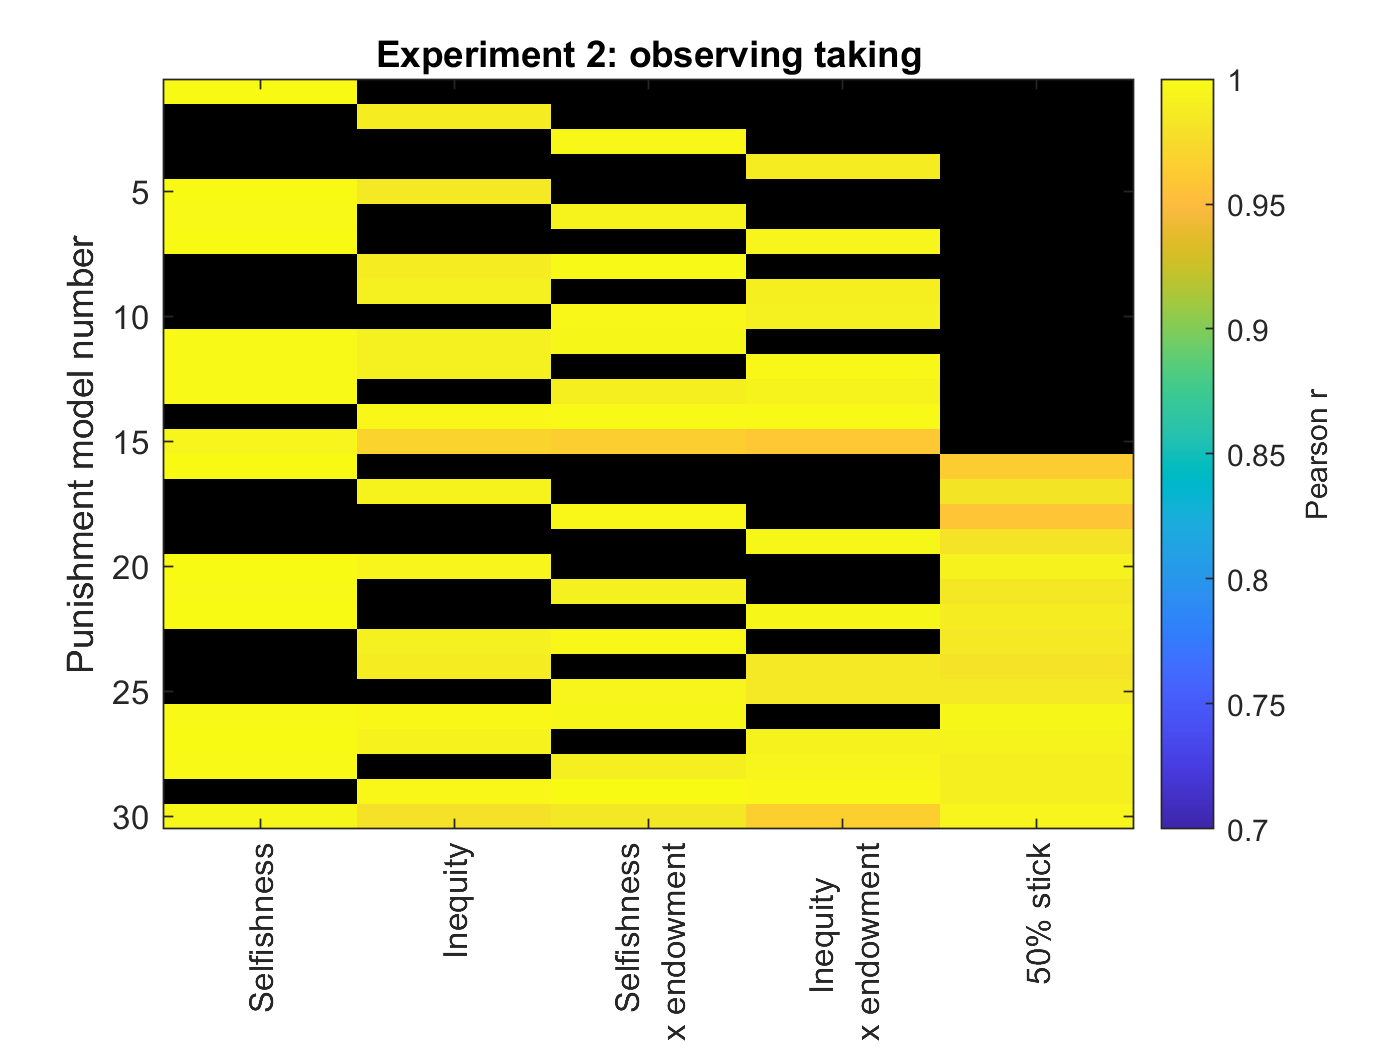

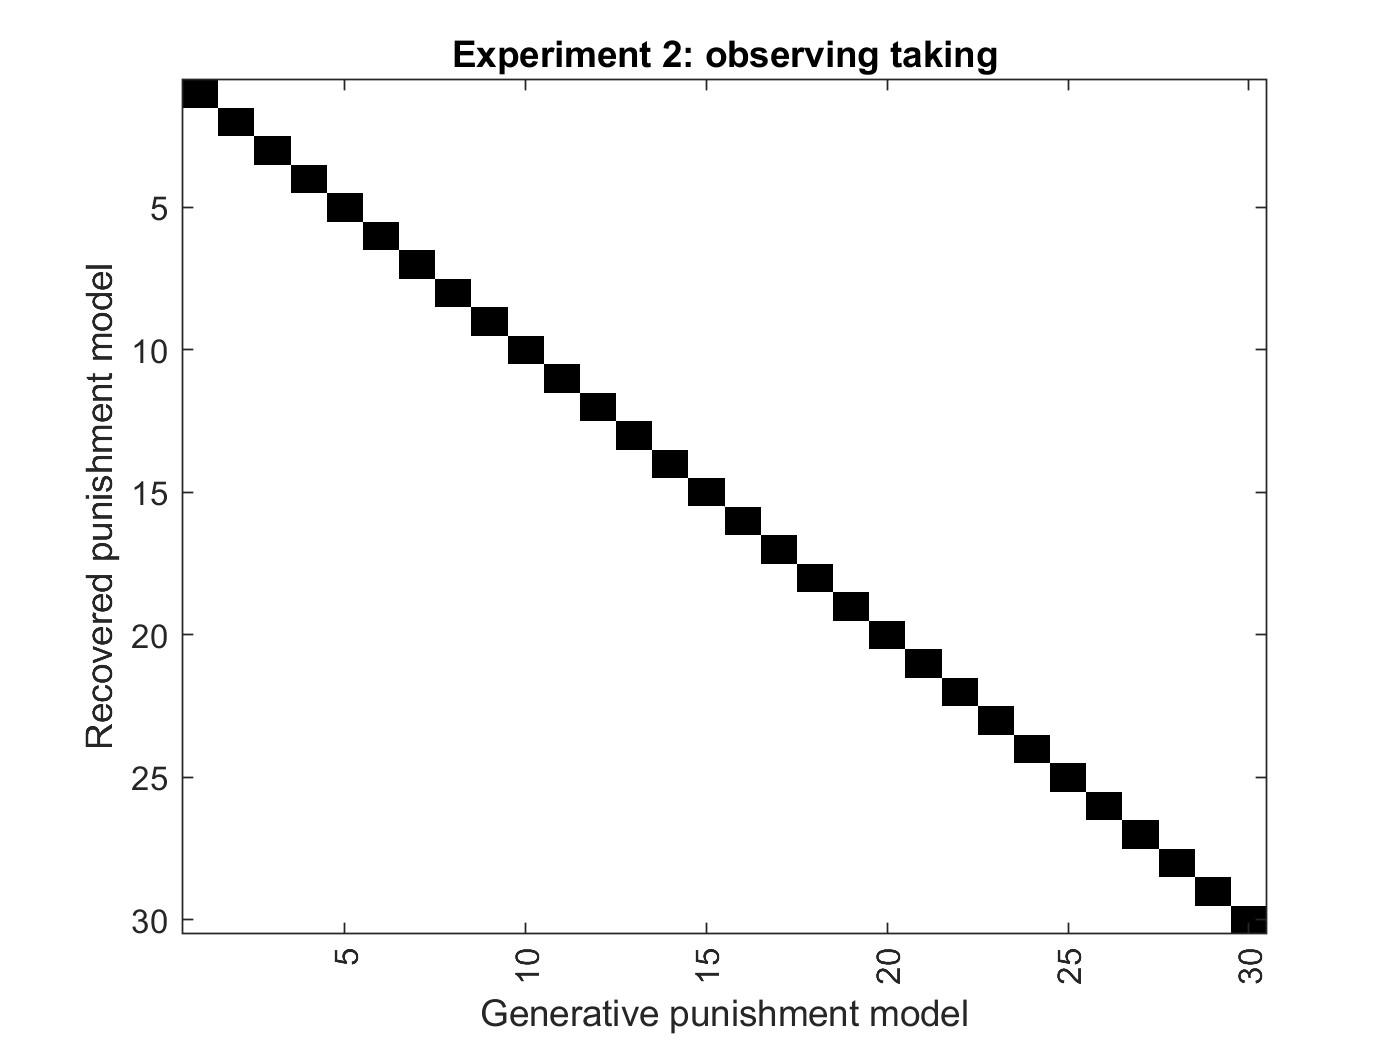

% get the BIC sum
matSumBic = squeeze(nansum(BICR{iExp},1));

% intialise the best model matrix
matBest = zeros(nModel,nModel);
for iModel=1:nModel
    tmp = min(matSumBic(iModel,:));
    idx = find(matSumBic(iModel,:)==tmp);
    tmp2 = matSumBic(iModel,:); tmp2(idx) = [];
    tmp3 = min(tmp2);
    if abs(tmp3-tmp)>30 % 1 if the model is best (delta BIC>30) or 0.5 if
        matBest(iModel,idx) = 1;
    elseif abs(tmp3-tmp)>3
        matBest(iModel,idx) = 0.5; % 0.5 if the model is best (delta BIC>3 but <30)
    else
        matBest(iModel,idx) = 0; % if not recovered
    end
    matComp(iModel,:) = matSumBic(iModel,:)-tmp;
end
% plot the model recovery matrix
%     figure(101);
figure
%     subplot(2,2,iExp);
imagesc(matBest);colormap(map2)
if (iExp)==1
    title('Experiment 1: observing taking')
    ylabel('Recovered feeling model')
    xlabel('Generative feeling model')
elseif (iExp)==2
    title('Experiment 2: observing giving')
    ylabel('Recovered feeling model')
    xlabel('Generative feeling model')
elseif (iExp)==3
    title('Experiment 1: observing taking')
    ylabel('Recovered punishment model')
    xlabel('Generative punishment model')
elseif (iExp)==4
    title('Experiment 2: observing taking')
    ylabel('Recovered punishment model')
    xlabel('Generative punishment model')
end
set(gca,'XTick',5:5:30,'XTickLabelRotation',90)
% fill the table
TModelRecovery{iExp} = array2table(matSumBic);
end

**Fig 8.** **Observers’** **punishment decisions reflect selfishness aversion and inequality aversion. **

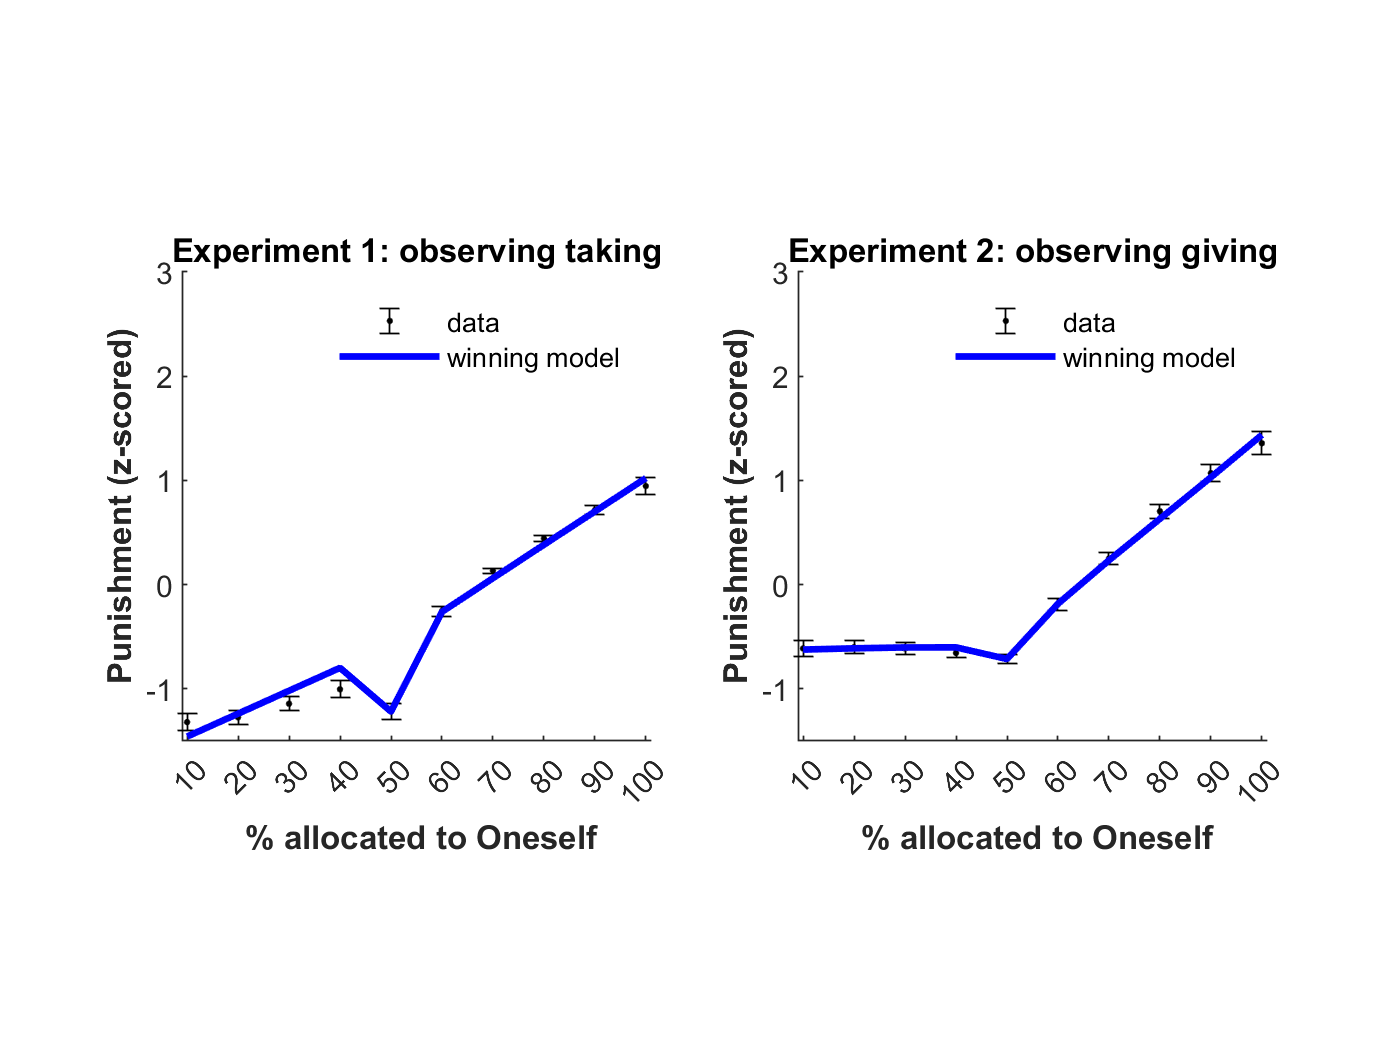

for iExp=[3 4]
    if iExp==3
        sublength = (length(unique(FeelingsData1.ID)));
    else
        sublength = (length(unique(FeelingsData2.ID)));
    end
    yM = [];ySD=[];ypredM=[];ypredSD=[];X=[];lUniqueSelf=[];
    for i=1:sublength  
        if iExp==3
            X = double(AllPunishmentData1(AllPunishmentData1.ID==i,[6,8,7,5]));
            figure(203);subplot(1,2,1);hold on;
        elseif iExp==4
            X = double(PunishmentData2(PunishmentData2.ID==i,[6,8,7,5]));
            figure(203);subplot(1,2,2);hold on;
        end
        lUniqueSelf = unique(X(:,1));
        lUniqueSelf(isnan(lUniqueSelf))=[];
        for iSelf=1:length(lUniqueSelf)
            idx =  X(:,1)==lUniqueSelf(iSelf);
            yM(i,iSelf)  = mean(X(idx,4));
            ySD(i,iSelf) = std(X(idx,4));
            ypredM(i,iSelf) = mean(predG{iExp,i,26}(idx));
            ypredSD(i,iSelf) = std(predG{iExp,i,26}(idx))./sqrt(sublength);
        end
    end
    errorbar(lUniqueSelf,nanmean(yM,1),nanstd(yM,1)./sqrt(sublength),'.k')
    plot(lUniqueSelf,nanmean(ypredM,1),'b','LineWidth',2)   
    xlabel('\bf{ % allocated to Oneself}')
    ylabel('\bf{Punishment} (z-scored)')
     legend({'data','winning model'})
    legend boxoff
    xlim([9 101])
    axis square
    if iExp==3
        title('Experiment 1: observing taking')
    elseif iExp==4
        title('Experiment 2: observing giving')
    end
    ylim([-1.5 3])
    set(gca,'XTick',10:10:100)
end

## **Out-of-sample prediction**

**Get the parameter in a more usable format**

for iExp=1:4
    if sum(iExp==[1,3])==1
        sublength = (length(unique(FeelingsData1.ID)));
    else
        sublength = (length(unique(FeelingsData2.ID)));
    end
    for iModel=1:nModel
        c=0;
        for i=1:sublength
            matParamRecGen{iExp,iModel}(i,:) = estimates{iExp,i,iModel}.muPhi;
        end
    end
end


**Figure S2 & S3**

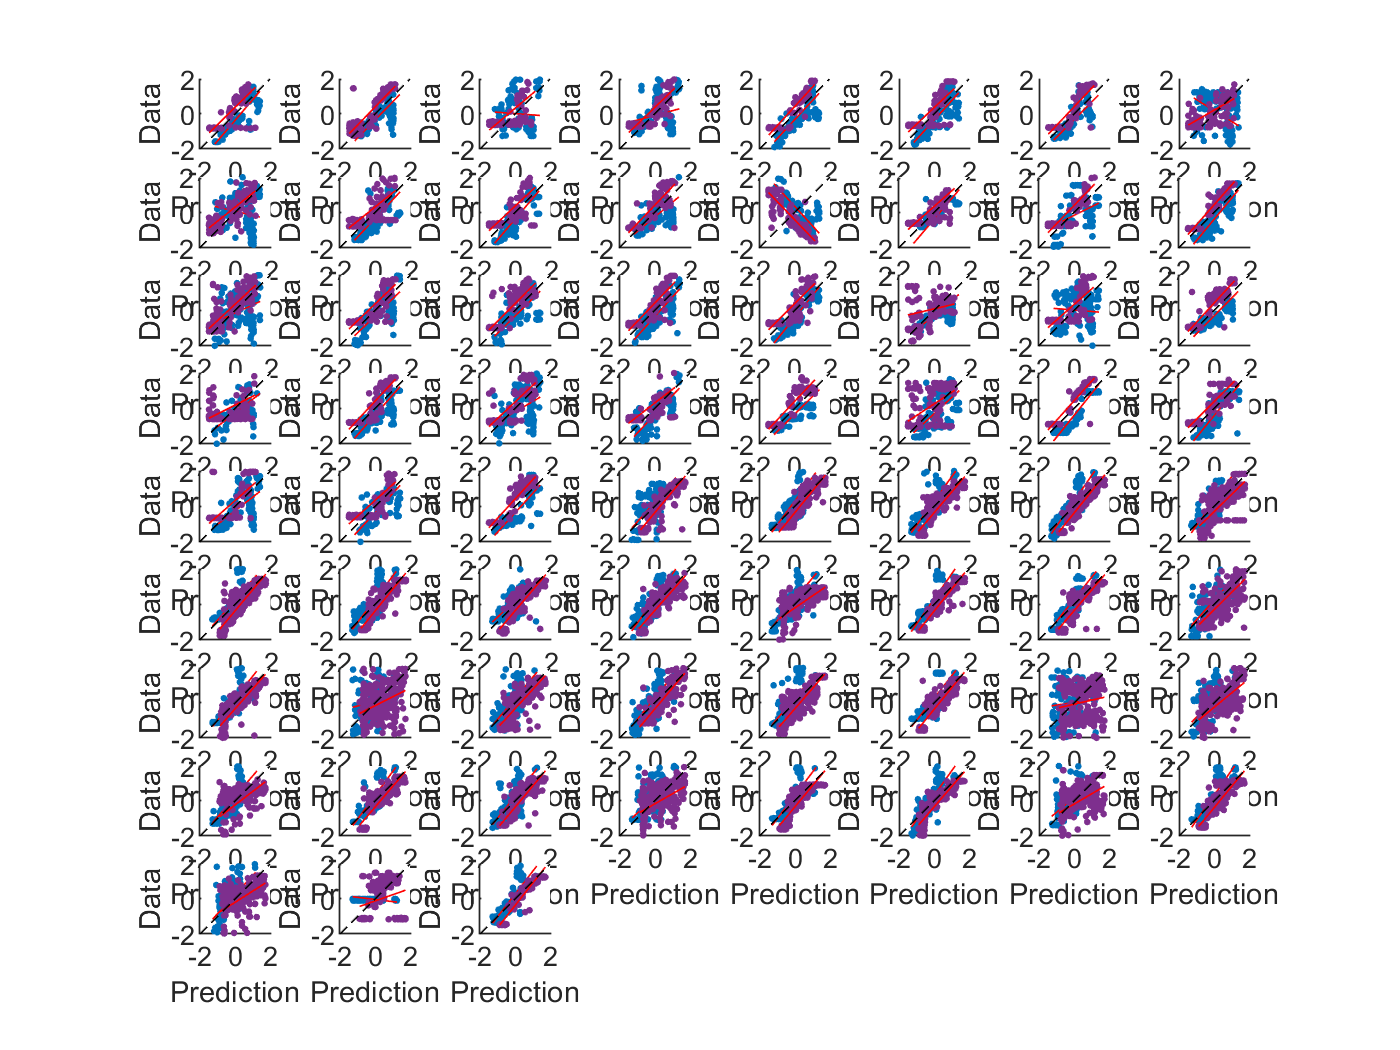

sublength = (length(unique(FeelingsData2.ID)));
%% expt 1 ==> expt 2
sublengthAll = (length(unique(FeelingsData1.ID))) + (length(unique(FeelingsData2.ID)));
counter = zeros(1,2);
Y=[];
lPred = [1 3];
for iExp=1:2
    for i=1:sublength
        counter(iExp) = counter(iExp) +1;
        if iExp==1
            data_ID_i = double(FeelingsData2(FeelingsData2.ID==i,[6,8,7,5]));
        elseif iExp==2
            data_ID_i = double(PunishmentData2(PunishmentData2.ID==i,[6,8,7,5]));
        end
        data_ID_iC = [data_ID_i(:,1:3) data_ID_i(:,4)]; % concatenate the new matrix
        data_ID_iC(:,5) = (data_ID_iC(:,1)==50);
        
        X = [data_ID_iC(:,1:2) data_ID_iC(:,1).*data_ID_iC(:,3) data_ID_iC(:,2).*data_ID_iC(:,3) data_ID_iC(:,5)];
        X = X./max(X);
        matIV = X; 
        
        Y(iExp,i,:) = data_ID_iC(:,4);
                
        for iModel =  26;%bestModel% loop through each generative model
            B = mean(matParamRecGen{lPred(iExp),iModel},1);% first feeling, then punishment, both from exp 1
            predCV{iExp,i,iModel} = B(1) + matIV(:,find(matParam(iModel,:)))*B(logical([0 matParam(iModel,:)]))';
            [matCVB(iExp,i,:),dev,stats] = glmfit(predCV{iExp,i,iModel},squeeze(Y(iExp,i,:)));
            matCVP(iExp,i,:) = stats.p;
            SSres = sum(stats.resid.^2);
            SStot = sum((Y(iExp,i,:)-mean(Y(iExp,i,:))).^2);
            matCVR2(iExp,i) = 1-(SSres/SStot); 
            matRMSE(iExp,i) = sqrt(mean(stats.resid.^2));
        end
        figure(1000+iExp);subplot(ceil(sqrt(sublengthAll)),round(sqrt(sublengthAll)),counter(iExp));hold on;
        scatter(predCV{iExp,i,iModel},squeeze(Y(iExp,i,:)),4,'filled')
        plot(predCV{iExp,i,iModel}, matCVB(iExp,i,1)+ matCVB(iExp,i,2).* predCV{iExp,i,iModel},'r')
        axis square
        ylim([-2 2])
        xlim([-2 2])
        plot(-2:2,-2:2,'--k')
        xlabel('Prediction')
        ylabel('Data')
%         title(['\beta_{0} = ',num2str(round(matCVB(iExp,i,1),2)),',\beta_{s} = ',num2str(round(matCVB(iExp,i,2),2)),', R^{2} = ',num2str(round(matCVR2(iExp,i),2))],'FontSize',8)
    end
end

sublength = (length(unique(FeelingsData1.ID)));

%%expt 2 ==> expt 1
lPred = [2 4];
for iExp=[3 4]
    Y=[];
    for i=1:sublength
        counter(iExp-2) = counter(iExp-2) +1;
        if iExp==3
            data_ID_i = double(FeelingsData1(FeelingsData1.ID==i,[6,8,7,5]));
        elseif iExp==4
            data_ID_i = double(AllPunishmentData1(AllPunishmentData1.ID==i,[6,8,7,5]));
        end
        data_ID_iC = [data_ID_i(:,1:3) data_ID_i(:,4)]; % concatenate the new matrix
        data_ID_iC(:,5) = (data_ID_iC(:,1)==50);
        
        X = [data_ID_iC(:,1:2) data_ID_iC(:,1).*data_ID_iC(:,3) data_ID_iC(:,2).*data_ID_iC(:,3) data_ID_iC(:,5)];
        X = X./max(X);
        matIV = X; 
        
        Y(iExp,i,:) = data_ID_iC(:,4);
                
        for iModel =  26;%bestModel% loop through each generative model
            B = mean(matParamRecGen{lPred(iExp-2),iModel},1);
            predCV{iExp,i,iModel} = B(1) + matIV(:,find(matParam(iModel,:)))*B(logical([0 matParam(iModel,:)]))';
            [matCVB(iExp,i,:),dev,stats] = glmfit(predCV{iExp,i,iModel},squeeze(Y(iExp,i,:)));
            matCVP(iExp,i,:) = stats.p;
            SSres = sum(stats.resid.^2);
            SStot = sum((Y(iExp,i,:)-mean(Y(iExp,i,:))).^2);
            matCVR2(iExp,i) = 1-(SSres/SStot); 
            matRMSE(iExp,i) = sqrt(mean(stats.resid.^2));
        end
        figure(1000+iExp-2);subplot(ceil(sqrt(sublengthAll)),round(sqrt(sublengthAll)),counter(iExp-2));hold on;
        scatter(predCV{iExp,i,iModel},squeeze(Y(iExp,i,:)),4,'filled')
        plot(predCV{iExp,i,iModel}, matCVB(iExp,i,1)+ matCVB(iExp,i,2).* predCV{iExp,i,iModel},'r')
        axis square
        ylim([-2 2])
        xlim([-2 2])
        plot(-2:2,-2:2,'--k')
        xlabel('Prediction')
        ylabel('Data')
%         title(['\beta_{0} = ',num2str(round(matCVB(iExp,i,1),2)),',\beta_{s} = ',num2str(round(matCVB(iExp,i,2),2)),', R^{2} = ',num2str(round(matCVR2(iExp,i),2))],'FontSize',8)
    end
end

**Get the table with the stats**

% get the CV stats for all
for iExp=1:2
    cvStatsAll{iExp} = nan(3,5);
    if iExp==1
        matCVBF(:,1) = [matCVB(1,:,1) matCVB(3,1:32,1)];
        matCVBF(:,2) = [matCVB(1,:,2) matCVB(3,1:32,2)];
        matCVR2F = [matCVR2(1,:) matCVR2(3,1:32)];
    else
        matCVBF(:,1) = [matCVB(2,:,1) matCVB(4,1:32,1)];
        matCVBF(:,2) = [matCVB(2,:,2) matCVB(4,1:32,2)];
        matCVR2F = [matCVR2(2,:) matCVR2(4,1:32)];
    end
    %%% r2
    ioi = ~(matCVBF(:,2)<-inf);
    i=0;
    i=i+1;cvStatsAll{iExp}(1,i) = nanmean(matCVR2F(ioi));
    i=i+1;cvStatsAll{iExp}(1,i) = nanstd(matCVR2F(ioi))/sqrt(sum(ioi));
    %%% slope
    ioi = ~(matCVBF(:,2)<-inf);
    i=0;
    i=i+1;cvStatsAll{iExp}(2,i) = mean(matCVBF(ioi,2));
    i=i+1;cvStatsAll{iExp}(2,i) = nanstd(matCVBF(ioi,2))/sqrt(sum(ioi));
    [h p ci stats] = ttest(matCVBF(ioi,2)-1);
    i=i+1;cvStatsAll{iExp}(2,i) = stats.df;
    i=i+1;cvStatsAll{iExp}(2,i) = stats.tstat;
    i=i+1;cvStatsAll{iExp}(2,i) = p;
    %%% intercept
    i=0;
    i=i+1;cvStatsAll{iExp}(3,i) = mean(matCVBF(ioi,1));
    i=i+1;cvStatsAll{iExp}(3,i) = nanstd(matCVBF(ioi,1))/sqrt(sum(ioi));
    [h p ci stats] = ttest(matCVBF(ioi,1));
    i=i+1;cvStatsAll{iExp}(3,i) = stats.df;
    i=i+1;cvStatsAll{iExp}(3,i) = stats.tstat;
    i=i+1;cvStatsAll{iExp}(3,i) = p;
    
    t = array2table(cvStatsAll{iExp});
    t.Properties.VariableNames = {'M' 'SE' 'df' 't' ,'p-value'};
    t.Properties.RowNames = {'r2','Slope' 'Intercept'};
    crossValidationTable{iExp} = t;    
end
disp('Feeling')

Feeling


disp(crossValidationTable{1})

                     M           SE       df        t        p-value
                 _________    ________    ___    ________    _______

    r2             0.50247    0.028965    NaN         NaN        NaN
    Slope          0.94129    0.062573     66    -0.93827    0.35153
    Intercept    -0.012129    0.035029     66    -0.34626    0.73025



disp('Punishment')

Punishment


disp(crossValidationTable{2})

                    M           SE       df        t       p-value
                 ________    ________    ___    _______    _______

    r2            0.63736    0.030265    NaN        NaN       NaN 
    Slope         0.93245    0.042636     66    -1.5843    0.1179 
    Intercept    0.025733    0.041619     66    0.61831    0.5385 



## **Observers’ affective responses are correlated with their punishment**

%% feelings ==> punishments
lPred = [1,2];
for iExp=1:2
    Y=[];
    if iExp==1
        sublength = (length(unique(FeelingsData1.ID)));
    else
        sublength = (length(unique(FeelingsData2.ID)));
    end
    for i=1:sublength
        if iExp==1
            data_ID_i = double(AllPunishmentData1(AllPunishmentData1.ID==i,[6,8,7,5]));
        elseif iExp==2
            data_ID_i = double(PunishmentData2(PunishmentData2.ID==i,[6,8,7,5]));
        end
        data_ID_iC = [data_ID_i(:,1:3) data_ID_i(:,4)];
        data_ID_iC(:,5) = (data_ID_iC(:,1)==50);% add the stick

        X = [data_ID_iC(:,1:2) data_ID_iC(:,1).*data_ID_iC(:,3) data_ID_iC(:,2).*data_ID_iC(:,3) data_ID_iC(:,5)];
        X = X./max(X);
        matIV = X;

        Y(iExp,i,:) = data_ID_i(:,4);
        for iModel =  26;%bestModel% loop through each generative model
            B = mean(matParamRecGen{lPred(iExp),iModel},1);
            pred{iExp,i,iModel} = B(1) + matIV(:,find(matParam(iModel,:)))*B(logical([0 matParam(iModel,:)]))';
            rFpredPobs{iExp}(i) = corr(pred{iExp,i,iModel},squeeze(Y(iExp,i,:)));
        end
    end
end

%% punishment ==> feeling
lPred = [3,4];
for iExp=[3 4]
    Y=[];
    if iExp==3
        sublength = (length(unique(FeelingsData1.ID)));       
    else
        sublength = (length(unique(FeelingsData2.ID)));      
    end
    for i=1:sublength
        if iExp==3            
            data_ID_i = double(FeelingsData1(FeelingsData1.ID==i,[6,8,7,5]));
        elseif iExp==4
            data_ID_i = double(FeelingsData2(FeelingsData2.ID==i,[6,8,7,5]));
        end
        data_ID_iC = [data_ID_i(:,1:3) data_ID_i(:,4)];
        data_ID_iC(:,5) = (data_ID_iC(:,1)==50);% add the stick
        
        X = [data_ID_iC(:,1:2) data_ID_iC(:,1).*data_ID_iC(:,3) data_ID_iC(:,2).*data_ID_iC(:,3) data_ID_iC(:,5)];
        X = X./max(X);
        matIV = X; 
        
        Y(iExp,i,:) = data_ID_i(:,4);
                
        for iModel =  26;%bestModel% loop through each generative model
            B = mean(matParamRecGen{lPred(iExp-2),iModel},1);
            pred{iExp,i,iModel} = B(1) + matIV(:,find(matParam(iModel,:)))*B(logical([0 matParam(iModel,:)]))';
            rFpredPobs{iExp}(i) = corr(pred{iExp,i,iModel},squeeze(Y(iExp,i,:))); 
        end
     end
end
% get the correlation stats
for iExp=1:4
    if sum(iExp==[1 3])
        nsub=35;
    else
        nsub=32;
    end    
    
    %%% corr pred
    i=0;
    i=i+1;corrPredStatsMeasure(iExp,i) = nanmean(rFpredPobs{iExp});
    i=i+1;corrPredStatsMeasure(iExp,i) = nanstd(rFpredPobs{iExp})/sqrt(nsub);
    [h p ci stats] = ttest(rFpredPobs{iExp});
    i=i+1;corrPredPredStatsMeasure(iExp,i) = ci(1);
    i=i+1;corrPredStatsMeasure(iExp,i) = ci(2);
    i=i+1;corrPredStatsMeasure(iExp,i) = stats.df;
    i=i+1;corrPredStatsMeasure(iExp,i) = stats.tstat;
    i=i+1;corrPredStatsMeasure(iExp,i) = p;
end

Correlation between observed data


                                    M            SE         CI_low      CI_high     df        t        p-value 
                               ___________    ________    __________    ________    __    _________    ________

    feeling2punishment_exp1    -0.00051282    0.015788     -0.034187    0.033162    31    -0.031059     0.97542
    feeling2punishment_exp2       0.034103    0.017085    0.00038033    0.067826    33       2.0575    0.047614
    punishment2feeling_exp1        0.01084    0.015653     -0.022548    0.044228    31      0.66217     0.51275
    punishment2feeling_exp2       0.019651     0.03459     -0.047565    0.086867    34      0.59414     0.55635



disp('Correlation between predicted data')

Correlation between predicted data


t = array2table(corrPredStatsMeasure);
t.Properties.VariableNames = {'M' 'SE' 'CI_low','CI_high' 'df' 't' ,'p-value'};
t.Properties.RowNames = {'feeling2punishment_exp1','feeling2punishment_exp2','punishment2feeling_exp1','punishment2feeling_exp2'};
affectivePunishmentCorrTable = t; 
disp(affectivePunishmentCorrTable)

                                  M           SE       CI_low    CI_high     df       t        p-value  
                               ________    ________    ______    ________    __    _______    __________

    feeling2punishment_exp1    -0.77791    0.036679      0       -0.69967    31    -20.279             0
    feeling2punishment_exp2    -0.70451    0.046188      0       -0.61475    34    -15.952             0
    punishment2feeling_exp1    -0.69444    0.047999      0       -0.59206    31    -13.834    8.3267e-15
    punishment2feeling_exp2    -0.56775    0.075202      0       -0.41932    33     -7.782    5.7526e-09



## **Differences in how selfishness aversion and inequality aversion impact feelings and actions**

#### **Fig 9**.** Transformed standardised coefficients for each factor, split by measures **

Get the standardised betas

for iExp=1:4
    %    get this subject data
    if sum(iExp==[1,3])==1
        lSub=unique(FeelingsData1.ID);
        sublength = (length(unique(FeelingsData1.ID)));
    else
        lSub=unique(FeelingsData2.ID);
        sublength = (length(unique(FeelingsData2.ID)));
    end
    cellParamAll{iExp} = nan(sublength,4);
    i=0;
    for iSub = 1:sublength
        i=i+1;
        % get this subject data
        if iExp==1
            SData_ID_i = double(FeelingsData1(FeelingsData1.ID==lSub(iSub),[6,8,7,5]));
        elseif iExp==2
            SData_ID_i = double(FeelingsData2(FeelingsData2.ID==lSub(iSub),[6,8,7,5]));
        elseif iExp==3
            SData_ID_i = double(AllPunishmentData1(AllPunishmentData1.ID==lSub(iSub),[6,8,7,5]));        
        elseif iExp==4
            SData_ID_i = double(PunishmentData2(PunishmentData2.ID==lSub(iSub),[6,8,7,5]));
        end
        SData_ID_iC= [SData_ID_i(:,1:3) SData_ID_i(:,4)]; % concatenate the new matrix
        SData_ID_iC(:,5) = (SData_ID_iC(:,1)==50);
        
        X = [SData_ID_iC(:,1:2) SData_ID_iC(:,1).*SData_ID_iC(:,3) SData_ID_iC(:,2).*SData_ID_iC(:,3) ];
        
        matIV  = [(X)]; % independent variables
        nObs   = size(X,1); % # observations
        nReg   = size(matIV(nObs,:),2); % # regressors
        y      = SData_ID_iC(1:nObs,4); % dependent variable to fit

        % add the stick to all of them, and add the squared term to all of
        % them
        X = [X SData_ID_iC(:,5) SData_ID_iC(:,2).^2];
        Z=[];
        for iReg=1:size(X,2)
            Z(:,iReg) = zscore(X(:,iReg));
        end
        % update independent variable matrix
        matIV  = Z; % independent variables
        nReg   = size(matIV(nObs,:),2); % # regressors        
        
        % Estimate model
        iModel = 26;
        [mu, dev, stats] = glmfit(matIV(:,find(matParam(iModel,:))),y,'Normal','Constant','off');
        % get the estimates
        estimatesCZ(iExp,i).muPhi = zeros(nReg+1,1);
        estimatesCZ(iExp,i).muPhi(find(logical([matParam(iModel,:)])),1) = mu;
        matParamAll(iExp,i,:) = mu;
        if iSub==25 & iExp>2
            matParamAll(iExp,i,:) = nan(4,1);
            cellParamAll{iExp}(i,:)  = nan(1,4);
        end
        cellParamAll{iExp}(i,:) = mu;
        estimatesCZ(iExp,i).sigmaPhi = zeros(nReg+1);
        tmp = zeros(1,nReg+1);
        tmp(find(logical([matParam(iModel,:)]))) = diag(stats.covb);
        estimatesCZ(iExp,i).sigmaPhi(boolean(eye(nReg+1))) = tmp; 
    end
end

% Selfishness VS inequality 
TakingFeelSelf = squeeze(matParamAll(1,1:32,1))';
GivingFeelSelf = squeeze(matParamAll(2,1:35,1))';
TakingFeelInequity = squeeze(matParamAll(1,1:32,2))';
GivingFeelInequity = squeeze(matParamAll(2,1:35,2))';
TakingPunSelf = squeeze(matParamAll(3,1:32,1))';
GivingPunSelf = squeeze(matParamAll(4,1:35,1))';
TakingPunInequity = squeeze(matParamAll(3,1:32,2))';
GivingPunInequity = squeeze(matParamAll(4,1:35,2))';


t = table(categorical([ones(length(TakingPunSelf),1); ones(length(GivingPunSelf),1)*2]),...
    [TakingFeelSelf;GivingFeelSelf], [TakingFeelInequity;GivingFeelInequity],...
    [-TakingPunSelf;-GivingPunSelf], [-TakingPunInequity;-GivingPunInequity],...
    'VariableNames',{'Experiment','FeelSelf','FeelIn','PunSelf','PunIn'});

within = table(categorical([1 1 2 2]'),categorical([1 2 1 2]'),'VariableNames',{'Response','Value'});
rm = fitrm(t,'FeelSelf-PunIn~Experiment','WithinDesign',within);
rm.Coefficients
ranovatbl = ranova(rm,'WithinModel','Response*Value')

multcompare(rm,'Response','By','Value')
multcompare(rm,'Value','By','Experiment')
multcompare(rm,'Response')

Get the figure

figure;hold on;
lParamCoord = [-0.85 -0.55 0.55 0.85];
lExpCoord = [2 5];
lColor =[0.5 0.5 0.5;0.5 0.5 0.5;0.5 0.5 0.5;0.5 0.5 0.5] ;
cellParamAll2 = cellParamAll([1 3 2 4]);
for iParam=1:2
    fH = gcf; 
    for iExp=1:4
        if mod(iExp,2)>0
            bar(lExpCoord(iParam)+lParamCoord(iExp),-sign((iParam==4)-0.5).*-sign(mod(iExp,2)-0.5).*nanmean(cellParamAll2{iExp}(:,iParam)),0.25,'EdgeColor',lColor(iExp,:),'FaceColor','none')
        else
            bar(lExpCoord(iParam)+lParamCoord(iExp),-sign((iParam==4)-0.5).*-sign(mod(iExp,2)-0.5).*nanmean(cellParamAll2{iExp}(:,iParam)),0.25,'EdgeColor',lColor(iExp,:),'FaceColor',lColor(iExp,:))
        end
    end
    if iParam==1
        legend({'Feelings','Punishment'},'AutoUpdate','off')
    end
    for iExp=1:4
        errorbar(lExpCoord(iParam)+lParamCoord(iExp),-sign((iParam==4)-0.5).*-sign(mod(iExp,2)-0.5).*nanmean(cellParamAll2{iExp}(:,iParam)),nanstd(cellParamAll2{iExp}(:,iParam))./sqrt(size((cellParamAll2{iExp}),1)),'k.')
    end
end
ylim([0 0.9])
xlabel('Selfishness                              Inequality')
set(gca,'XTick',[2-0.70 2+0.70 5-0.70 5+0.70],'XTickLabel',{'Take','Give','Take','Give'})
ylabel('Standardized coefficient')